# HAMR-6 SE(2) locomotion study

## 3D reconstruction of trajectory and kinematics

The goal of this section is to take the properties of HAMR reconstruct it in 3D and add the trajectory of the robot to it. Here's a marked up top view of HAMR-6 and that will be the subject of 3D reconstruction study. **All units are in mm.**

### Respecting form-factor symmetry

In this subsection, we shall use our bounding box measurements and respect the symmetry of the design. This would mean, as shown in the top-view, the bounding boxes shall have equal opposing sides.

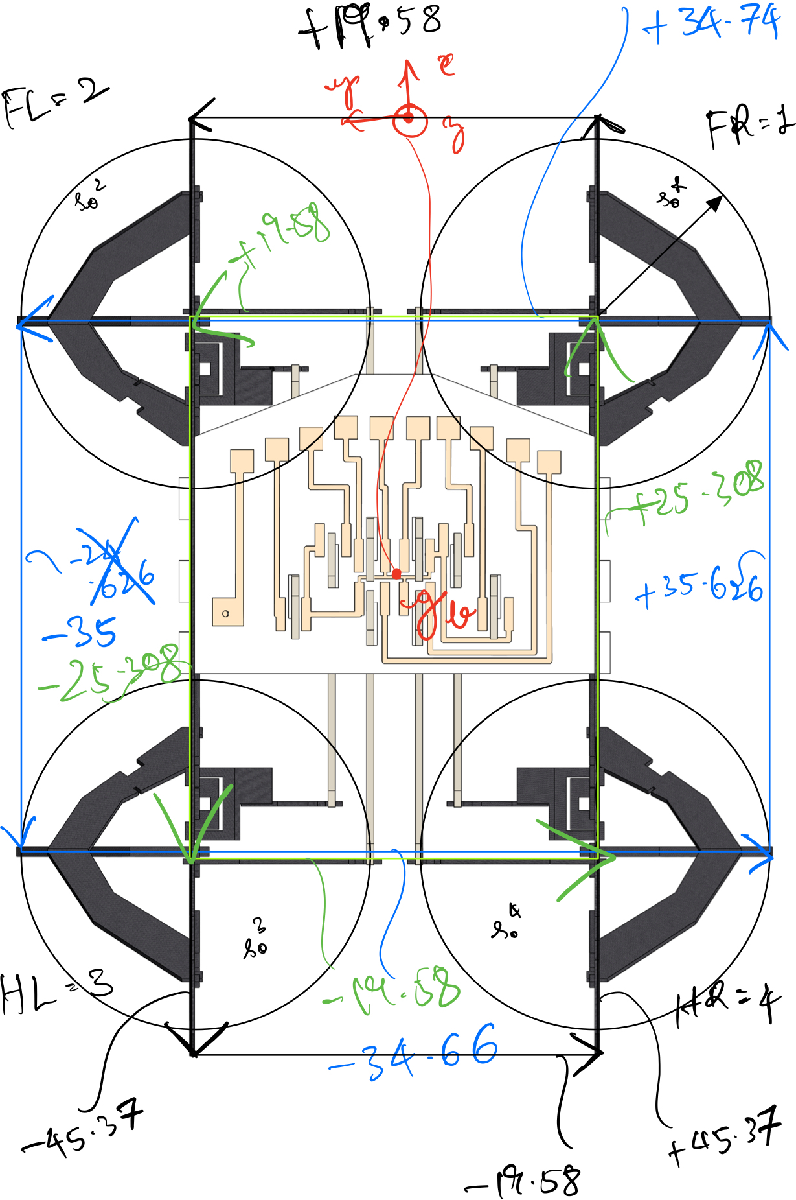

There and 3 bounding boxes above-- the green one connects the bases of each spherical five-bar transmission (SFB), the blue one connects the feet-tips, and the black one connects the tips of the body excluding the legs. These boxes are at different levels, and hence we need to handle that to get the right 3D reconstruction. Hence, these bounding boxes are defined as a set of cyclic vectors forming a closed shape (boxes in the quadrupedal case)-- the vectors are defined in a global rest frame that is aligned with the body frame before the motion begins. Assume the initial point of the first vector (tail) to be the origin for this set of vectors. We shall exploit the fact that all the these bounding boxes are centered around the body frame of the robot. NOTE: THE BOXES ARE AT DIFFERENT Z-LEVELS. This must be accounted for when doing the transformations.

Let's first round off all quantities to 3 significant digits instead of 4 significant digit measurement.

% add utilities function to the path
addpath 'Data'\ 'Utility Functions'\;

% foot bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
foot_bound = [[0, 34.74, 0]; [-35, 0, 0]; [0, -34.66, 0]; [35.626, 0, 0]]

foot_bound =          0   34.7400         0
  -35.0000         0         0
         0  -34.6600         0
   35.6260         0         0


foot_bound = boundboxmean(foot_bound, true) % true because it is designed to be a square

foot_bound =      0    35     0
   -35     0     0
     0   -35     0
    35     0     0


% hip bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
hip_bound = [[0, 19.58, 0]; [-25.308, 0, 0]; [0, -19.58, 0]; [25.308, 0, 0]]

hip_bound =          0   19.5800         0
  -25.3080         0         0
         0  -19.5800         0
   25.3080         0         0


hip_bound = boundboxmean(hip_bound, false)

hip_bound =          0   19.6000         0
  -25.3000         0         0
         0  -19.6000         0
   25.3000         0         0


% body w/o leg bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% there's a top and a bottom version for this bounding box and this will be addressed in the next section.
bodywoleg_bound = [[0, 19.58, 0]; [-45.37, 0, 0]; [0, -19.58, 0]; [45.37, 0, 0]]

bodywoleg_bound =          0   19.5800         0
  -45.3700         0         0
         0  -19.5800         0
   45.3700         0         0


bodywoleg_bound = boundboxmean(bodywoleg_bound, false)

bodywoleg_bound =          0   19.6000         0
  -45.4000         0         0
         0  -19.6000         0
   45.4000         0         0


Here we shall set the body length of the robot by the largest dimension of all bounding boxes.

bl = bodywoleg_bound(4, 1);

### Translational transformations to body center

Now, let's compute the transforms from the body frame to the frames of interest-- we shall break down transformations into translations and rotations. Here's an isometric view of the 3D reconstruction of the robot we need and also the z change between various bounding boxes.

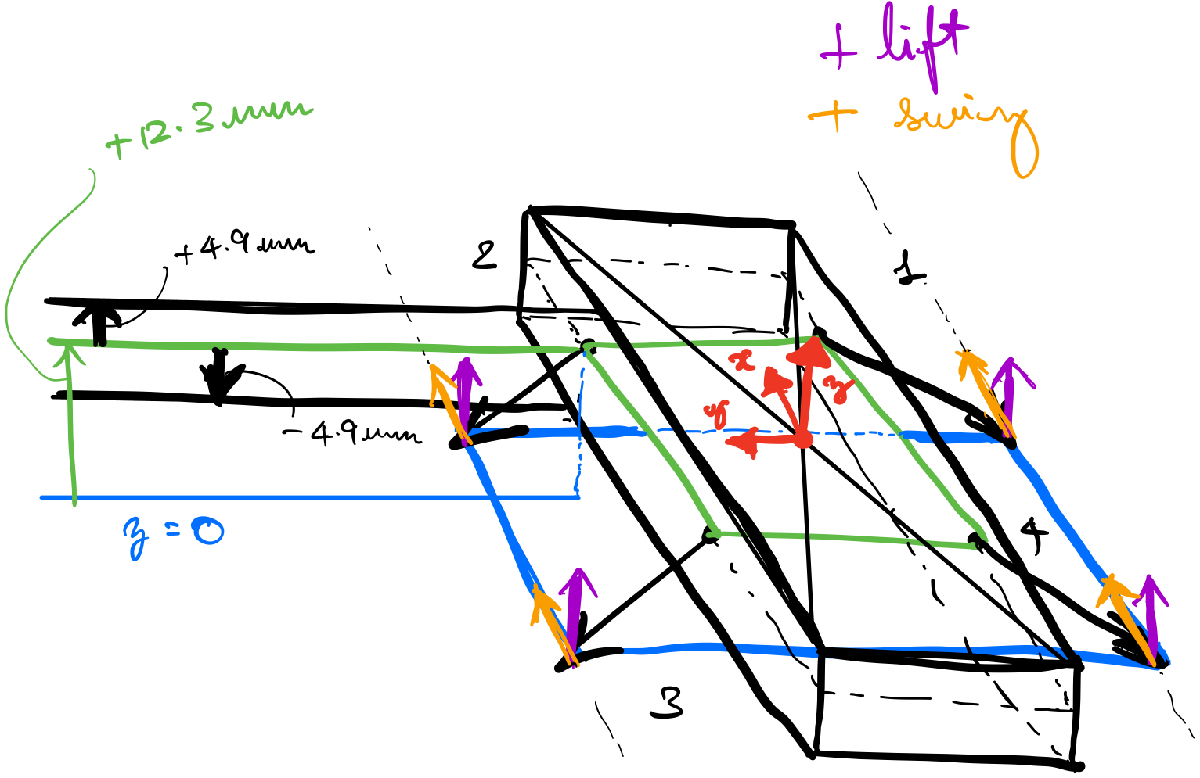

% z-change in HAMR6 with markers on (body center in the middle of the top plate in 2017 Ben Goldberg's: 10.1109/IROS.2017.8206249; ""UPDATED 20230420"": the body frame is in the middle of the hip bound box)
z_body2hipbox = [0, 0, 0]; % z = -4.19 UPDATED to 0 on ""20230420""
z_body2bodyboundboxT = [0, 0, +4.19]; % z = +4.19 UPDATED on ""20230420""
z_body2bodyboundboxB = [0, 0, -4.19*1]; % z = -4.19*2 UPDATED to -4.19 on ""20230420""

% find the location of frame 1b hip-frame from the center of the robot-- translational sub-group of SE3
%%%%%%%%%% just h denotes SE2 transformations: ht translations, hR rotations
%%%%%%%%%% h3 denotes SE3 transformations: ht3 translations, hR3 rotations
%%%%%%%%%% small 'h' stands for vector form of se3/2 transformation, 'H' stands for the group action form of se3/2 transformation
h3_b__hip = boundbox2ht3transform(hip_bound) + repmat(z_body2hipbox, [size(hip_bound, 1), 1]); % repeat over rows
h3_b__1b = h3_b__hip(1, :);
h3_b__2b = h3_b__hip(2, :);
h3_b__3b = h3_b__hip(3, :);
h3_b__4b = h3_b__hip(4, :);

% find the location of the top and bottom bounding boxes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TOP
h3_b__bboundT = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxT, [size(bodywoleg_bound, 1), 1]);
h3_b__1cT = h3_b__bboundT(1, :);
h3_b__2cT = h3_b__bboundT(2, :);
h3_b__3cT = h3_b__bboundT(3, :);
h3_b__4cT = h3_b__bboundT(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BOT
h3_b__bboundB = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxB, [size(bodywoleg_bound, 1), 1]);
h3_b__1cB = h3_b__bboundB(1, :);
h3_b__2cB = h3_b__bboundB(2, :);
h3_b__3cB = h3_b__bboundB(3, :);
h3_b__4cB = h3_b__bboundB(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% JOIN (add links to join the top and bottom sides)
h3_b__bboundB2T = h3_b__bboundT - h3_b__bboundB;

% Finally, let's find the transformations to these frames (no rotations since they all have the same orientation as the body frame)
% SE3 transformations for the hip frame ##############################################################
H3_b__hip = t_SE3(h3_b__hip); 
H3_b__1b = H3_b__hip{1};
H3_b__2b = H3_b__hip{2};
H3_b__3b = H3_b__hip{3};
H3_b__4b = H3_b__hip{4};
% SE3 transformations for the top bounding box #######################################################
H3_b__bboundT = t_SE3(h3_b__bboundT); 
H3_b__1cT = H3_b__bboundT{1};
H3_b__2cT = H3_b__bboundT{2};
H3_b__3cT = H3_b__bboundT{3};
H3_b__4cT = H3_b__bboundT{4};
% SE3 transformations for the bot bounding box #######################################################
H3_b__bboundB = t_SE3(h3_b__bboundB);
H3_b__1cB = H3_b__bboundB{1};
H3_b__2cB = H3_b__bboundB{2};
H3_b__3cB = H3_b__bboundB{3};
H3_b__4cB = H3_b__bboundB{4};
% compile the transforms
H3_b__ib = H3_b__hip;
H3_b__icT = H3_b__bboundT;
H3_b__icB = H3_b__bboundB;

Let's plot what we have so far and visualize it from a few different view points.

% gr_col = [100, 100, 100]/255;
% figure('units','pixels','position',[0 0 1920 1080],'Color','w')
% % plot the hip bound box %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% quiver3(h3_b__hip(:, 1), h3_b__hip(:, 2), h3_b__hip(:, 3), hip_bound(:, 1), hip_bound(:, 2), hip_bound(:, 3),...
%     'LineWidth', 2, 'Color', gr_col, 'AutoScale', 'off', 'ShowArrowHead', 'off');
% % set some props %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% hold on; view(-37.5, 30); axis square equal; axis([-50 50 -50 50 -20 20]); xlabel('x'); ylabel('y'); zlabel('z');
% % plot the body bound boxes and complete it %%%%%%%%%%%%%%%%%%%
% quiver3(h3_b__bboundT(:, 1), h3_b__bboundT(:, 2), h3_b__bboundT(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
%     'LineWidth', 1.5, 'Color', gr_col, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % top box
% quiver3(h3_b__bboundB(:, 1), h3_b__bboundB(:, 2), h3_b__bboundB(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
%     'LineWidth', 1.5, 'Color', gr_col, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % bottom box
% quiver3(h3_b__bboundB(:, 1), h3_b__bboundB(:, 2), h3_b__bboundB(:, 3), h3_b__bboundB2T(:, 1), h3_b__bboundB2T(:, 2), h3_b__bboundB2T(:, 3),...
%     'LineWidth', 1.5, 'Color', gr_col, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % connection
% % plot the body frame %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% quiver3(zeros(3,1), zeros(3,1), zeros(3,1), [5, 0, 0]', [0, 5, 0]', [0, 0, 5]', 'LineWidth', 2, 'Color', 'k', 'AutoScale', 'off');
% % plot the hip frames %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% for i = 1:size(h3_b__hip, 1)
%     quiver3(h3_b__hip(i,1)*ones(3,1), h3_b__hip(i,2)*ones(3,1), h3_b__hip(i,3)*ones(3,1), [2, 0, 0]', [0, 2, 0]', [0, 0, 2]',...
%     'LineWidth', 2, 'Color', 'k', 'AutoScale', 'off');
% end

### Full SE(3) transformations

Let's model the legs about the SFB using lift and swing angles inputs-- the positive lift and swing angles are shown in the 3D reconstruction sketch.

Thus, the leg transformations from the SFB are characterized by a rotation along Z for a swing angle ($-\alpha$ for the left side of the body and $\alpha$  for he right side of the body) followed by a rotation along X for a lift angle ($\beta$ for the left side of the body and $-\beta$  for he right side of the body)-- let's call this frame 1bR (for rotated 1b frame).

syms alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4 real
h3_ib__ibR_z = [alpha_1, -alpha_2, -alpha_3, alpha_4]'; h3_ib__ibR_x = [beta_1, -beta_2, -beta_3, beta_4]';
H3_ib__ibR_z = rotz_SE3(h3_ib__ibR_z); H3_ib__ibR_x = rotx_SE3(h3_ib__ibR_x);
H3_1b__1bR = simplify(H3_ib__ibR_z{1}*H3_ib__ibR_x{1});
H3_2b__2bR = simplify(H3_ib__ibR_z{2}*H3_ib__ibR_x{2});
H3_3b__3bR = simplify(H3_ib__ibR_z{3}*H3_ib__ibR_x{3});
H3_4b__4bR = simplify(H3_ib__ibR_z{4}*H3_ib__ibR_x{4});

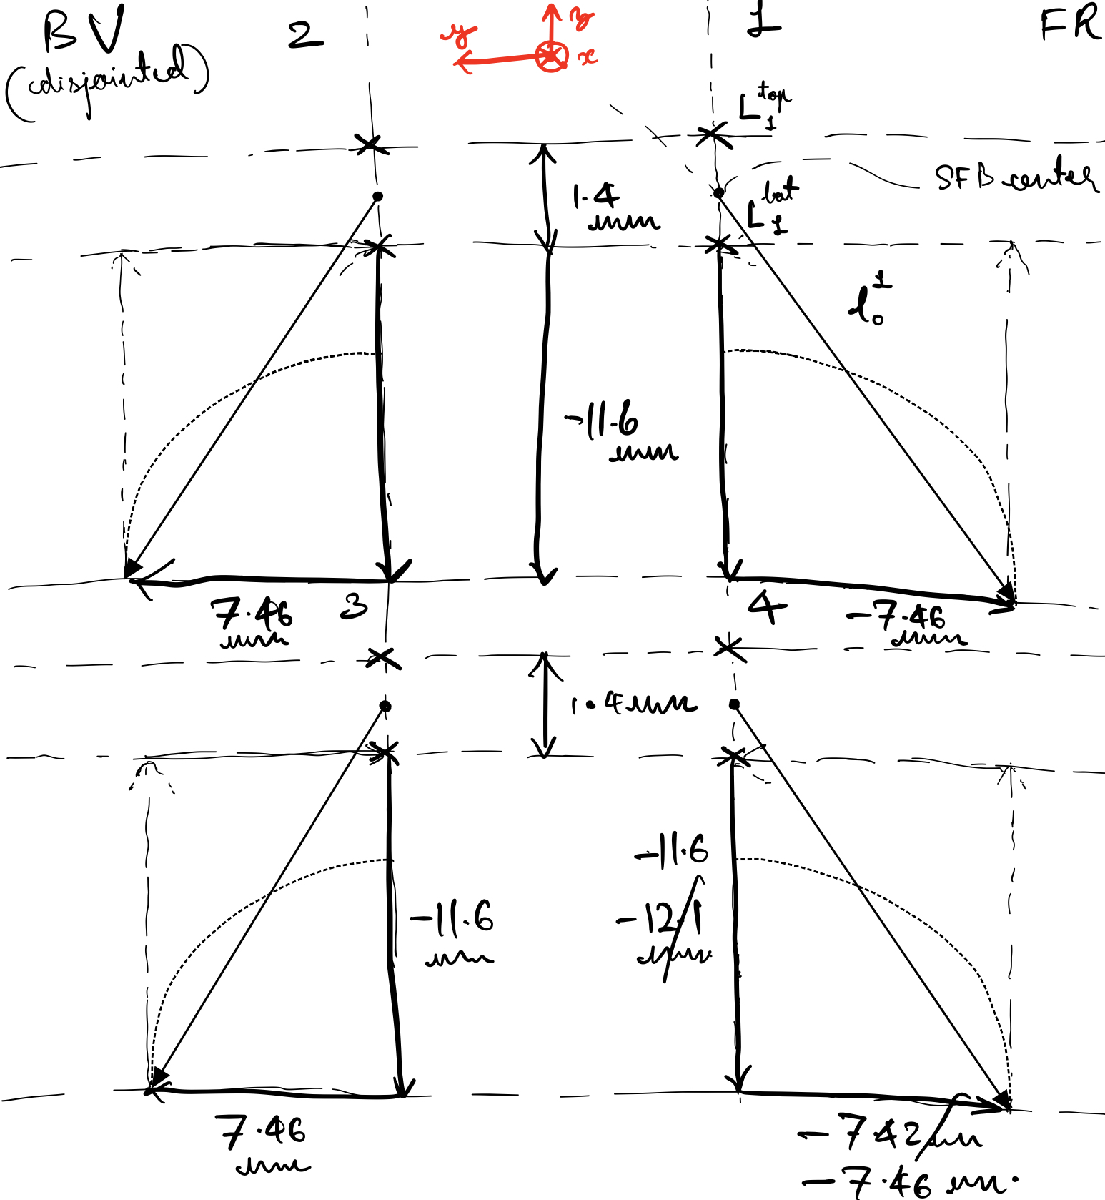

Then, we translate along the directions specified in the figure above-- this will give us the foot-tip frames.

h3_1bR__1 = [0, -7.46, -11.6];
h3_2bR__2 = [0, +7.46, -11.6];
h3_3bR__3 = [0, +7.46, -11.6];
h3_4bR__4 = [0, -7.46, -11.6];
H3_1bR__1 = t_SE3(h3_1bR__1);
H3_2bR__2 = t_SE3(h3_2bR__2);
H3_3bR__3 = t_SE3(h3_3bR__3);
H3_4bR__4 = t_SE3(h3_4bR__4);
% Compute the complete transformation from hip-frame to the foot
H3_1b__1 = simplify(H3_1b__1bR*H3_1bR__1)

$$H3\_1b\_\_1 = \left(\begin{array}{cccc} \cos\left(\alpha_{1}\right) & -\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \frac{\sin\left(\alpha_{1}\right)\,\left(373\,\cos\left(\beta_{1}\right)+580\,\sin\left(\beta_{1}\right)\right)}{50}\\ \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right) & \cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & -\frac{\cos\left(\alpha_{1}\right)\,\left(373\,\cos\left(\beta_{1}\right)+580\,\sin\left(\beta_{1}\right)\right)}{50}\\ 0 & -\sin\left(\beta_{1}\right) & \cos\left(\beta_{1}\right) & \frac{373\,\sin\left(\beta_{1}\right)}{50}-\frac{58\,\cos\left(\beta_{1}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_2b__2 = simplify(H3_2b__2bR*H3_2bR__2)

$$H3\_2b\_\_2 = \left(\begin{array}{cccc} \cos\left(\alpha_{2}\right) & \cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{\sin\left(\alpha_{2}\right)\,\left(373\,\cos\left(\beta_{2}\right)+580\,\sin\left(\beta_{2}\right)\right)}{50}\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right) & -\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{\cos\left(\alpha_{2}\right)\,\left(373\,\cos\left(\beta_{2}\right)+580\,\sin\left(\beta_{2}\right)\right)}{50}\\ 0 & \sin\left(\beta_{2}\right) & \cos\left(\beta_{2}\right) & \frac{373\,\sin\left(\beta_{2}\right)}{50}-\frac{58\,\cos\left(\beta_{2}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_3b__3 = simplify(H3_3b__3bR*H3_3bR__3)

$$H3\_3b\_\_3 = \left(\begin{array}{cccc} \cos\left(\alpha_{3}\right) & \cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{\sin\left(\alpha_{3}\right)\,\left(373\,\cos\left(\beta_{3}\right)+580\,\sin\left(\beta_{3}\right)\right)}{50}\\ -\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right) & -\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{\cos\left(\alpha_{3}\right)\,\left(373\,\cos\left(\beta_{3}\right)+580\,\sin\left(\beta_{3}\right)\right)}{50}\\ 0 & \sin\left(\beta_{3}\right) & \cos\left(\beta_{3}\right) & \frac{373\,\sin\left(\beta_{3}\right)}{50}-\frac{58\,\cos\left(\beta_{3}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_4b__4 = simplify(H3_4b__4bR*H3_4bR__4)

$$H3\_4b\_\_4 = \left(\begin{array}{cccc} \cos\left(\alpha_{4}\right) & -\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right) & -\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \frac{\sin\left(\alpha_{4}\right)\,\left(373\,\cos\left(\beta_{4}\right)+580\,\sin\left(\beta_{4}\right)\right)}{50}\\ \sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right) & \cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & -\frac{\cos\left(\alpha_{4}\right)\,\left(373\,\cos\left(\beta_{4}\right)+580\,\sin\left(\beta_{4}\right)\right)}{50}\\ 0 & -\sin\left(\beta_{4}\right) & \cos\left(\beta_{4}\right) & \frac{373\,\sin\left(\beta_{4}\right)}{50}-\frac{58\,\cos\left(\beta_{4}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% % % Let's compute the transforms from the body as well
% H3_b__1bR_z = simplify(H3_b__1b*H3_ib__ibR_z{1})
H3_b__1 = simplify(H3_b__1b*H3_1b__1)

$$H3\_b\_\_1 = \left(\begin{array}{cccc} \cos\left(\alpha_{1}\right) & -\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \frac{\sin\left(\alpha_{1}\right)\,\left(373\,\cos\left(\beta_{1}\right)+580\,\sin\left(\beta_{1}\right)\right)}{50}+\frac{253}{20}\\ \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right) & \cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & -\frac{\cos\left(\alpha_{1}\right)\,\left(373\,\cos\left(\beta_{1}\right)+580\,\sin\left(\beta_{1}\right)\right)}{50}-\frac{49}{5}\\ 0 & -\sin\left(\beta_{1}\right) & \cos\left(\beta_{1}\right) & \frac{373\,\sin\left(\beta_{1}\right)}{50}-\frac{58\,\cos\left(\beta_{1}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% H3_b__2bR_z = simplify(H3_b__2b*H3_ib__ibR_z{2})
H3_b__2 = simplify(H3_b__2b*H3_2b__2)

$$H3\_b\_\_2 = \left(\begin{array}{cccc} \cos\left(\alpha_{2}\right) & \cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{\sin\left(\alpha_{2}\right)\,\left(373\,\cos\left(\beta_{2}\right)+580\,\sin\left(\beta_{2}\right)\right)}{50}+\frac{253}{20}\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right) & -\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{\cos\left(\alpha_{2}\right)\,\left(373\,\cos\left(\beta_{2}\right)+580\,\sin\left(\beta_{2}\right)\right)}{50}+\frac{49}{5}\\ 0 & \sin\left(\beta_{2}\right) & \cos\left(\beta_{2}\right) & \frac{373\,\sin\left(\beta_{2}\right)}{50}-\frac{58\,\cos\left(\beta_{2}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% H3_b__3bR_z = simplify(H3_b__3b*H3_ib__ibR_z{3})
H3_b__3 = simplify(H3_b__3b*H3_3b__3)

$$H3\_b\_\_3 = \left(\begin{array}{cccc} \cos\left(\alpha_{3}\right) & \cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{\sin\left(\alpha_{3}\right)\,\left(373\,\cos\left(\beta_{3}\right)+580\,\sin\left(\beta_{3}\right)\right)}{50}-\frac{253}{20}\\ -\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right) & -\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{\cos\left(\alpha_{3}\right)\,\left(373\,\cos\left(\beta_{3}\right)+580\,\sin\left(\beta_{3}\right)\right)}{50}+\frac{49}{5}\\ 0 & \sin\left(\beta_{3}\right) & \cos\left(\beta_{3}\right) & \frac{373\,\sin\left(\beta_{3}\right)}{50}-\frac{58\,\cos\left(\beta_{3}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% H3_b__4bR_z = simplify(H3_b__4b*H3_ib__ibR_z{4})
H3_b__4 = simplify(H3_b__4b*H3_4b__4)

$$H3\_b\_\_4 = \left(\begin{array}{cccc} \cos\left(\alpha_{4}\right) & -\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right) & -\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \frac{\sin\left(\alpha_{4}\right)\,\left(373\,\cos\left(\beta_{4}\right)+580\,\sin\left(\beta_{4}\right)\right)}{50}-\frac{253}{20}\\ \sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right) & \cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & -\frac{\cos\left(\alpha_{4}\right)\,\left(373\,\cos\left(\beta_{4}\right)+580\,\sin\left(\beta_{4}\right)\right)}{50}-\frac{49}{5}\\ 0 & -\sin\left(\beta_{4}\right) & \cos\left(\beta_{4}\right) & \frac{373\,\sin\left(\beta_{4}\right)}{50}-\frac{58\,\cos\left(\beta_{4}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_ib__ibR = {H3_1b__1bR; H3_2b__2bR; H3_3b__3bR; H3_4b__4bR};
H3_ibR__i = {H3_1bR__1; H3_2bR__2; H3_3bR__3; H3_4bR__4};
H3_ib__i = {H3_1b__1; H3_2b__2; H3_3b__3; H3_4b__4};
% H3_b__ibR_z = {H3_b__1bR_z, H3_b__2bR_z, H3_b__3bR_z, H3_b__4bR_z};
H3_b__i = {H3_b__1; H3_b__2; H3_b__3; H3_b__4};

% body transformation from a global rest frame
syms x y z a b c real                               % can't use alpha, beta, and gamma due to geometric results
H3_e__b = t_SE3([x, y, z])*rotx_SE3(a)*roty_SE3(b)*rotz_SE3(c) % 20230421 --- CHANGED TO XYZ rotation order to match HAMR 6's dataset

$$H3\_e\_\_b = \left(\begin{array}{cccc} \cos\left(b\right)\,\cos\left(c\right) & -\cos\left(b\right)\,\sin\left(c\right) & \sin\left(b\right) & x\\ \cos\left(a\right)\,\sin\left(c\right)-\cos\left(c\right)\,\sin\left(a\right)\,\sin\left(b\right) & \cos\left(a\right)\,\cos\left(c\right)+\sin\left(a\right)\,\sin\left(b\right)\,\sin\left(c\right) & \cos\left(b\right)\,\sin\left(a\right) & y\\ -\sin\left(a\right)\,\sin\left(c\right)-\cos\left(a\right)\,\cos\left(c\right)\,\sin\left(b\right) & \cos\left(a\right)\,\sin\left(b\right)\,\sin\left(c\right)-\cos\left(c\right)\,\sin\left(a\right) & \cos\left(a\right)\,\cos\left(b\right) & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Let's compute the full-jacobian for each leg using the adjoint inverse operation
% -----------------------------------------------------------------------------------------------------------------------------
% Jacobians to the leg from the body -- MAP IN TWIST COORDINATES
% -----------------------------------------------------------------------------------------------------------------------------
J3_b__1 = adj_adjinv_SE3(H3_b__1, -1)

$$J3\_b\_\_1 = \left(\begin{array}{cccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0 & 0\\ -\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right) & -\sin\left(\beta_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \cos\left(\beta_{1}\right) & 0 & 0 & 0\\ \sin\left(\alpha_{1}\right)\,\left(\frac{58\,\cos\left(\beta_{1}\right)}{5}-\frac{373\,\sin\left(\beta_{1}\right)}{50}\right) & -\frac{\cos\left(\alpha_{1}\right)\,\left(580\,\cos\left(\beta_{1}\right)-373\,\sin\left(\beta_{1}\right)\right)}{50} & \frac{49\,\cos\left(\alpha_{1}\right)}{5}+\frac{373\,\cos\left(\beta_{1}\right)}{50}+\frac{253\,\sin\left(\alpha_{1}\right)}{20}+\frac{58\,\sin\left(\beta_{1}\right)}{5} & \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ \frac{58\,\cos\left(\alpha_{1}\right)}{5}+\frac{49\,\sin\left(\beta_{1}\right)}{5} & \frac{58\,\sin\left(\alpha_{1}\right)}{5}+\frac{253\,\sin\left(\beta_{1}\right)}{20} & \frac{\cos\left(\beta_{1}\right)\,\left(253\,\cos\left(\alpha_{1}\right)-196\,\sin\left(\alpha_{1}\right)\right)}{20} & -\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right) & -\sin\left(\beta_{1}\right)\\ -\frac{373\,\cos\left(\alpha_{1}\right)}{50}-\frac{49\,\cos\left(\beta_{1}\right)}{5} & -\frac{253\,\cos\left(\beta_{1}\right)}{20}-\frac{373\,\sin\left(\alpha_{1}\right)}{50} & \frac{\sin\left(\beta_{1}\right)\,\left(253\,\cos\left(\alpha_{1}\right)-196\,\sin\left(\alpha_{1}\right)\right)}{20} & -\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \cos\left(\beta_{1}\right) \end{array}\right)$$

J3_b__2 = adj_adjinv_SE3(H3_b__2, -1)

$$J3\_b\_\_2 = \left(\begin{array}{cccccc} \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & 0 & 0 & 0 & 0\\ \cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right) & \sin\left(\beta_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & -\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \cos\left(\beta_{2}\right) & 0 & 0 & 0\\ -\frac{\sin\left(\alpha_{2}\right)\,\left(580\,\cos\left(\beta_{2}\right)-373\,\sin\left(\beta_{2}\right)\right)}{50} & -\frac{\cos\left(\alpha_{2}\right)\,\left(580\,\cos\left(\beta_{2}\right)-373\,\sin\left(\beta_{2}\right)\right)}{50} & -\frac{49\,\cos\left(\alpha_{2}\right)}{5}-\frac{373\,\cos\left(\beta_{2}\right)}{50}-\frac{253\,\sin\left(\alpha_{2}\right)}{20}-\frac{58\,\sin\left(\beta_{2}\right)}{5} & \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right) & 0\\ \frac{58\,\cos\left(\alpha_{2}\right)}{5}+\frac{49\,\sin\left(\beta_{2}\right)}{5} & -\frac{58\,\sin\left(\alpha_{2}\right)}{5}-\frac{253\,\sin\left(\beta_{2}\right)}{20} & \frac{\cos\left(\beta_{2}\right)\,\left(253\,\cos\left(\alpha_{2}\right)-196\,\sin\left(\alpha_{2}\right)\right)}{20} & \cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right) & \sin\left(\beta_{2}\right)\\ \frac{373\,\cos\left(\alpha_{2}\right)}{50}+\frac{49\,\cos\left(\beta_{2}\right)}{5} & -\frac{253\,\cos\left(\beta_{2}\right)}{20}-\frac{373\,\sin\left(\alpha_{2}\right)}{50} & -\frac{\sin\left(\beta_{2}\right)\,\left(253\,\cos\left(\alpha_{2}\right)-196\,\sin\left(\alpha_{2}\right)\right)}{20} & -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & -\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \cos\left(\beta_{2}\right) \end{array}\right)$$

J3_b__3 = adj_adjinv_SE3(H3_b__3, -1)

$$J3\_b\_\_3 = \left(\begin{array}{cccccc} \cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right) & 0 & 0 & 0 & 0\\ \cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right) & \sin\left(\beta_{3}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & -\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \cos\left(\beta_{3}\right) & 0 & 0 & 0\\ -\frac{\sin\left(\alpha_{3}\right)\,\left(580\,\cos\left(\beta_{3}\right)-373\,\sin\left(\beta_{3}\right)\right)}{50} & -\frac{\cos\left(\alpha_{3}\right)\,\left(580\,\cos\left(\beta_{3}\right)-373\,\sin\left(\beta_{3}\right)\right)}{50} & \frac{253\,\sin\left(\alpha_{3}\right)}{20}-\frac{373\,\cos\left(\beta_{3}\right)}{50}-\frac{49\,\cos\left(\alpha_{3}\right)}{5}-\frac{58\,\sin\left(\beta_{3}\right)}{5} & \cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right) & 0\\ \frac{58\,\cos\left(\alpha_{3}\right)}{5}+\frac{49\,\sin\left(\beta_{3}\right)}{5} & \frac{253\,\sin\left(\beta_{3}\right)}{20}-\frac{58\,\sin\left(\alpha_{3}\right)}{5} & -\frac{\cos\left(\beta_{3}\right)\,\left(253\,\cos\left(\alpha_{3}\right)+196\,\sin\left(\alpha_{3}\right)\right)}{20} & \cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right) & \sin\left(\beta_{3}\right)\\ \frac{373\,\cos\left(\alpha_{3}\right)}{50}+\frac{49\,\cos\left(\beta_{3}\right)}{5} & \frac{253\,\cos\left(\beta_{3}\right)}{20}-\frac{373\,\sin\left(\alpha_{3}\right)}{50} & \frac{\sin\left(\beta_{3}\right)\,\left(253\,\cos\left(\alpha_{3}\right)+196\,\sin\left(\alpha_{3}\right)\right)}{20} & -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & -\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \cos\left(\beta_{3}\right) \end{array}\right)$$

J3_b__4 = adj_adjinv_SE3(H3_b__4, -1)

$$J3\_b\_\_4 = \left(\begin{array}{cccccc} \cos\left(\alpha_{4}\right) & \sin\left(\alpha_{4}\right) & 0 & 0 & 0 & 0\\ -\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right) & -\sin\left(\beta_{4}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \cos\left(\beta_{4}\right) & 0 & 0 & 0\\ \sin\left(\alpha_{4}\right)\,\left(\frac{58\,\cos\left(\beta_{4}\right)}{5}-\frac{373\,\sin\left(\beta_{4}\right)}{50}\right) & -\frac{\cos\left(\alpha_{4}\right)\,\left(580\,\cos\left(\beta_{4}\right)-373\,\sin\left(\beta_{4}\right)\right)}{50} & \frac{49\,\cos\left(\alpha_{4}\right)}{5}+\frac{373\,\cos\left(\beta_{4}\right)}{50}-\frac{253\,\sin\left(\alpha_{4}\right)}{20}+\frac{58\,\sin\left(\beta_{4}\right)}{5} & \cos\left(\alpha_{4}\right) & \sin\left(\alpha_{4}\right) & 0\\ \frac{58\,\cos\left(\alpha_{4}\right)}{5}+\frac{49\,\sin\left(\beta_{4}\right)}{5} & \frac{58\,\sin\left(\alpha_{4}\right)}{5}-\frac{253\,\sin\left(\beta_{4}\right)}{20} & -\frac{\cos\left(\beta_{4}\right)\,\left(253\,\cos\left(\alpha_{4}\right)+196\,\sin\left(\alpha_{4}\right)\right)}{20} & -\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right) & -\sin\left(\beta_{4}\right)\\ -\frac{373\,\cos\left(\alpha_{4}\right)}{50}-\frac{49\,\cos\left(\beta_{4}\right)}{5} & \frac{253\,\cos\left(\beta_{4}\right)}{20}-\frac{373\,\sin\left(\alpha_{4}\right)}{50} & -\frac{\sin\left(\beta_{4}\right)\,\left(253\,\cos\left(\alpha_{4}\right)+196\,\sin\left(\alpha_{4}\right)\right)}{20} & -\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \cos\left(\beta_{4}\right) \end{array}\right)$$

% compile
J3_b__i = {J3_b__1; J3_b__2; J3_b__3; J3_b__4};

% -----------------------------------------------------------------------------------------------------------------------------
% Jacobians to the leg frame from the corresponding hip frame 
% -----------------------------------------------------------------------------------------------------------------------------
% +ve swing velocity is measured about the (-Z)-axis for the left side of the body and (+Z)-axis for the right side of the body
% +ve lift velocity is measured about the (+Y)-axis for the left side of the body and (-Y)-axis for the right side of the body
alpha_circ_1 = [0, 0, 1, 0, 0, 0]'; alpha_circ_2 = [0, 0, -1, 0, 0, 0]'; alpha_circ_3 = [0, 0, -1, 0, 0, 0]'; alpha_circ_4 = [0, 0, 1, 0, 0, 0]';
beta_circ_1 = [0, -1, 0, 0, 0, 0]'; beta_circ_2 = [0, 1, 0, 0, 0, 0]'; beta_circ_3 = [0, 1, 0, 0, 0, 0]'; beta_circ_4 = [0, -1, 0, 0, 0, 0]';
circ_1 = [alpha_circ_1, beta_circ_1]; circ_2 = [alpha_circ_2, beta_circ_2]; circ_3 = [alpha_circ_3, beta_circ_3]; circ_4 = [alpha_circ_4, beta_circ_4];

% Get the jacobians from the hip frame -- first set of columns correspond to swing velocities, alpha_dot and the second set of columns correspond to lift
% velocites, beta_dot
J3_1b__1 = adj_adjinv_SE3(H3_1b__1, -1)*circ_1

$$J3\_1b\_\_1 = \left(\begin{array}{cc} 0 & -\sin\left(\alpha_{1}\right)\\ -\sin\left(\beta_{1}\right) & -\cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right)\\ \cos\left(\beta_{1}\right) & -\cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)\\ \frac{373\,\cos\left(\beta_{1}\right)}{50}+\frac{58\,\sin\left(\beta_{1}\right)}{5} & \frac{\cos\left(\alpha_{1}\right)\,\left(580\,\cos\left(\beta_{1}\right)-373\,\sin\left(\beta_{1}\right)\right)}{50}\\ 0 & -\frac{58\,\sin\left(\alpha_{1}\right)}{5}\\ 0 & \frac{373\,\sin\left(\alpha_{1}\right)}{50} \end{array}\right)$$

J3_2b__2 = adj_adjinv_SE3(H3_2b__2, -1)*circ_2

$$J3\_2b\_\_2 = \left(\begin{array}{cc} 0 & -\sin\left(\alpha_{2}\right)\\ -\sin\left(\beta_{2}\right) & \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right)\\ -\cos\left(\beta_{2}\right) & -\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)\\ \frac{373\,\cos\left(\beta_{2}\right)}{50}+\frac{58\,\sin\left(\beta_{2}\right)}{5} & -\frac{\cos\left(\alpha_{2}\right)\,\left(580\,\cos\left(\beta_{2}\right)-373\,\sin\left(\beta_{2}\right)\right)}{50}\\ 0 & -\frac{58\,\sin\left(\alpha_{2}\right)}{5}\\ 0 & -\frac{373\,\sin\left(\alpha_{2}\right)}{50} \end{array}\right)$$

J3_3b__3 = adj_adjinv_SE3(H3_3b__3, -1)*circ_3

$$J3\_3b\_\_3 = \left(\begin{array}{cc} 0 & -\sin\left(\alpha_{3}\right)\\ -\sin\left(\beta_{3}\right) & \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right)\\ -\cos\left(\beta_{3}\right) & -\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)\\ \frac{373\,\cos\left(\beta_{3}\right)}{50}+\frac{58\,\sin\left(\beta_{3}\right)}{5} & -\frac{\cos\left(\alpha_{3}\right)\,\left(580\,\cos\left(\beta_{3}\right)-373\,\sin\left(\beta_{3}\right)\right)}{50}\\ 0 & -\frac{58\,\sin\left(\alpha_{3}\right)}{5}\\ 0 & -\frac{373\,\sin\left(\alpha_{3}\right)}{50} \end{array}\right)$$

J3_4b__4 = adj_adjinv_SE3(H3_4b__4, -1)*circ_4

$$J3\_4b\_\_4 = \left(\begin{array}{cc} 0 & -\sin\left(\alpha_{4}\right)\\ -\sin\left(\beta_{4}\right) & -\cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right)\\ \cos\left(\beta_{4}\right) & -\cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)\\ \frac{373\,\cos\left(\beta_{4}\right)}{50}+\frac{58\,\sin\left(\beta_{4}\right)}{5} & \frac{\cos\left(\alpha_{4}\right)\,\left(580\,\cos\left(\beta_{4}\right)-373\,\sin\left(\beta_{4}\right)\right)}{50}\\ 0 & -\frac{58\,\sin\left(\alpha_{4}\right)}{5}\\ 0 & \frac{373\,\sin\left(\alpha_{4}\right)}{50} \end{array}\right)$$

% compile
J3_ib__i = {J3_1b__1; J3_2b__2; J3_3b__3; J3_4b__4};

% -----------------------------------------------------------------------------------------------------------------------------
% FULL Jacobian to the leg frame from
% -----------------------------------------------------------------------------------------------------------------------------
J3_i = computefulljacobianSE3( {J3_b__1, J3_b__2, J3_b__3, J3_b__4}, {J3_1b__1, J3_2b__2, J3_3b__3, J3_4b__4}, 4);

% -----------------------------------------------------------------------------------------------------------------------------
% Contact Submanifold for HAMR 6 and corresponding colors
% -----------------------------------------------------------------------------------------------------------------------------
% S = gencontactsubmanifolds(4) %%%%%%%%%%%%%%%% the ordered submanifolds % this needs more work-- shelved for now
S = [ [1; 
       2; 
       3; 
       4], nan(4, 3);
      [1, 2;
       2, 3;
       3, 4;
       4, 1;
       1, 3;
       2, 4], nan(6, 2);
      [1, 2, 3;
       2, 3, 4;
       3, 4, 1;
       4, 1, 2], nan(4, 1);
      [1, 2, 3,4] ];

Slvl = size(S, 2) - sum(isnan(S), 2); % a row vector showing the level of the contact state
col = zeros(size(S, 1), 3); % everything black first
% col(Slvl < 2, :) = repmat([100, 100, 100]/255, [sum(Slvl < 2, 1), 1]); %%%%%%%%%%% removed this because it is confusing with the nullspace
col(Slvl == 2, :) = [255,127,0;
                    231,41,138;
                    44,123,182;
                    77,175,74;
                    215,25,28;
                    96,0,220]/255; % color states

% compile the shapes into the parameterization of the shape space 'r'
R = [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4];
% define the body's SE(3) twist in vector form
B = [x, y, z, a, b, c];

% Convert these to functions and store it in a struct for later access
% % % % fH3_b__1bR_z = matlabFunction(H3_b__1, 'Vars', R);
% % % % fH3_b__2bR_z = matlabFunction(H3_b__2, 'Vars', R);
% % % % fH3_b__3bR_z = matlabFunction(H3_b__3, 'Vars', R);
% % % % fH3_b__4bR_z = matlabFunction(H3_b__4, 'Vars', R);
% % % % fH3_b__ibR_z = {fH3_b__1bR_z, fH3_b__2bR_z, fH3_b__3bR_z, fH3_b__4bR_z};
fH3_e__b = matlabFunction(H3_e__b, 'Vars', B);

fH3_b__1 = matlabFunction(H3_b__1, 'Vars', R);
fH3_b__2 = matlabFunction(H3_b__2, 'Vars', R);
fH3_b__3 = matlabFunction(H3_b__3, 'Vars', R);
fH3_b__4 = matlabFunction(H3_b__4, 'Vars', R);
fH3_b__i = {fH3_b__1, fH3_b__2, fH3_b__3, fH3_b__4};

fJ3_b__1 = matlabFunction(J3_b__1, 'Vars', R);
fJ3_b__2 = matlabFunction(J3_b__2, 'Vars', R);
fJ3_b__3 = matlabFunction(J3_b__3, 'Vars', R);
fJ3_b__4 = matlabFunction(J3_b__4, 'Vars', R);
fJ3_b__i = {fJ3_b__1, fJ3_b__2, fJ3_b__3, fJ3_b__4};

fH3_1b__1 = matlabFunction(H3_1b__1, 'Vars', R);
fH3_2b__2 = matlabFunction(H3_2b__2, 'Vars', R);
fH3_3b__3 = matlabFunction(H3_3b__3, 'Vars', R);
fH3_4b__4 = matlabFunction(H3_4b__4, 'Vars', R);
fH3_ib__i = {fH3_1b__1, fH3_2b__2, fH3_3b__3, fH3_4b__4};

fJ3_1b__1 = matlabFunction(J3_1b__1, 'Vars', R);
fJ3_2b__2 = matlabFunction(J3_2b__2, 'Vars', R);
fJ3_3b__3 = matlabFunction(J3_3b__3, 'Vars', R);
fJ3_4b__4 = matlabFunction(J3_4b__4, 'Vars', R);
fJ3_ib__i = {fJ3_1b__1, fJ3_2b__2, fJ3_3b__3, fJ3_4b__4};
fJ3_1 = matlabFunction(J3_i{1}, 'Vars', R);
fJ3_2 = matlabFunction(J3_i{2}, 'Vars', R);
fJ3_3 = matlabFunction(J3_i{3}, 'Vars', R);
fJ3_4 = matlabFunction(J3_i{4}, 'Vars', R);
fJ3_i = {fJ3_1, fJ3_2, fJ3_3, fJ3_4};

% Initialize the struct and start storing computed quantities
HAMR_6 = [];


HAMR_6 =

     []



HAMR_6_SE3 = [];
% measured bounds
HAMR_6_SE3.bounds.hip = hip_bound; % hip bounds
HAMR_6_SE3.bounds.body = bodywoleg_bound; % body box bounds
% numeric transforms
HAMR_6_SE3.transforms.num.H3_b__ib = H3_b__ib; % hip transforms
HAMR_6_SE3.transforms.num.H3_b__icT = H3_b__icT; % bounding top transforms
HAMR_6_SE3.transforms.num.H3_b__icB = H3_b__icB; % bounding bot transforms
% symbolic transforms
HAMR_6_SE3.transforms.sym.H3_ib__ibR = H3_ib__ibR; % hip to swing-lift rotated hip
HAMR_6_SE3.transforms.sym.H3_ib__ibR_z = H3_ib__ibR_z; % hip to swing rotated hip
HAMR_6_SE3.transforms.sym.H3_ib__ibR_x = H3_ib__ibR_x; % swing rotated hip to lift rotated hip
HAMR_6_SE3.transforms.sym.H3_ibR__i = H3_ibR__i; % swing-lift rotated hip to foot
HAMR_6_SE3.transforms.sym.H3_ib__i = H3_ib__i; % hip to foot
HAMR_6_SE3.transforms.sym.H3_b__i = H3_b__i; % body to foot
HAMR_6_SE3.transforms.sym.H3_e__b = H3_e__b; % body to foot
HAMR_6_SE3.transforms.sym.J3_i = J3_i; % full jacobian from body and hip to the feet
% functional transforms
HAMR_6_SE3.transforms.fun.fH3_b__i = fH3_b__i; % body to foot transform functions
HAMR_6_SE3.transforms.fun.fJ3_b__i = fJ3_b__i; % body to foot jacobian functions
HAMR_6_SE3.transforms.fun.fH3_ib__i = fH3_ib__i; % hip to foot transform functions
HAMR_6_SE3.transforms.fun.fJ3_ib__i = fJ3_ib__i; % hip to foot jacobian functions
HAMR_6_SE3.transforms.fun.fH3_e__b = fH3_e__b; % origin to body transform function
HAMR_6_SE3.transforms.fun.fJ3_i = fJ3_i; % body to foot full jacobian function
% contact submanifold information
HAMR_6_SE3.contact.submanifolds = S; % list of contact states
HAMR_6_SE3.contact.submanifold_level = Slvl; % level corresponding to the list of contact states (level-2 is our focus)
HAMR_6_SE3.contact.color = col; % color for each contact state (custom colors are added just for the level-2 states)
% configuration space information
HAMR_6_SE3.config.B = B;
HAMR_6_SE3.config.R = R;
% parameters
HAMR_6_SE3.params.bl = bl;

% assign it to the parent dataset
HAMR_6.SE3 = HAMR_6_SE3;

% Store the data
if exist('Data\HAMR6_SE3_kinematics.mat', 'file') == 2
    save('Data\HAMR6_SE3_kinematics.mat', 'HAMR_6', '-append'); % appends data if it already exists
else
    save('Data\HAMR6_SE3_kinematics.mat', 'HAMR_6', '-mat'); % else create a new file
end

Let's plot the HAMR configuration and to plot the data to see if these transformations work!

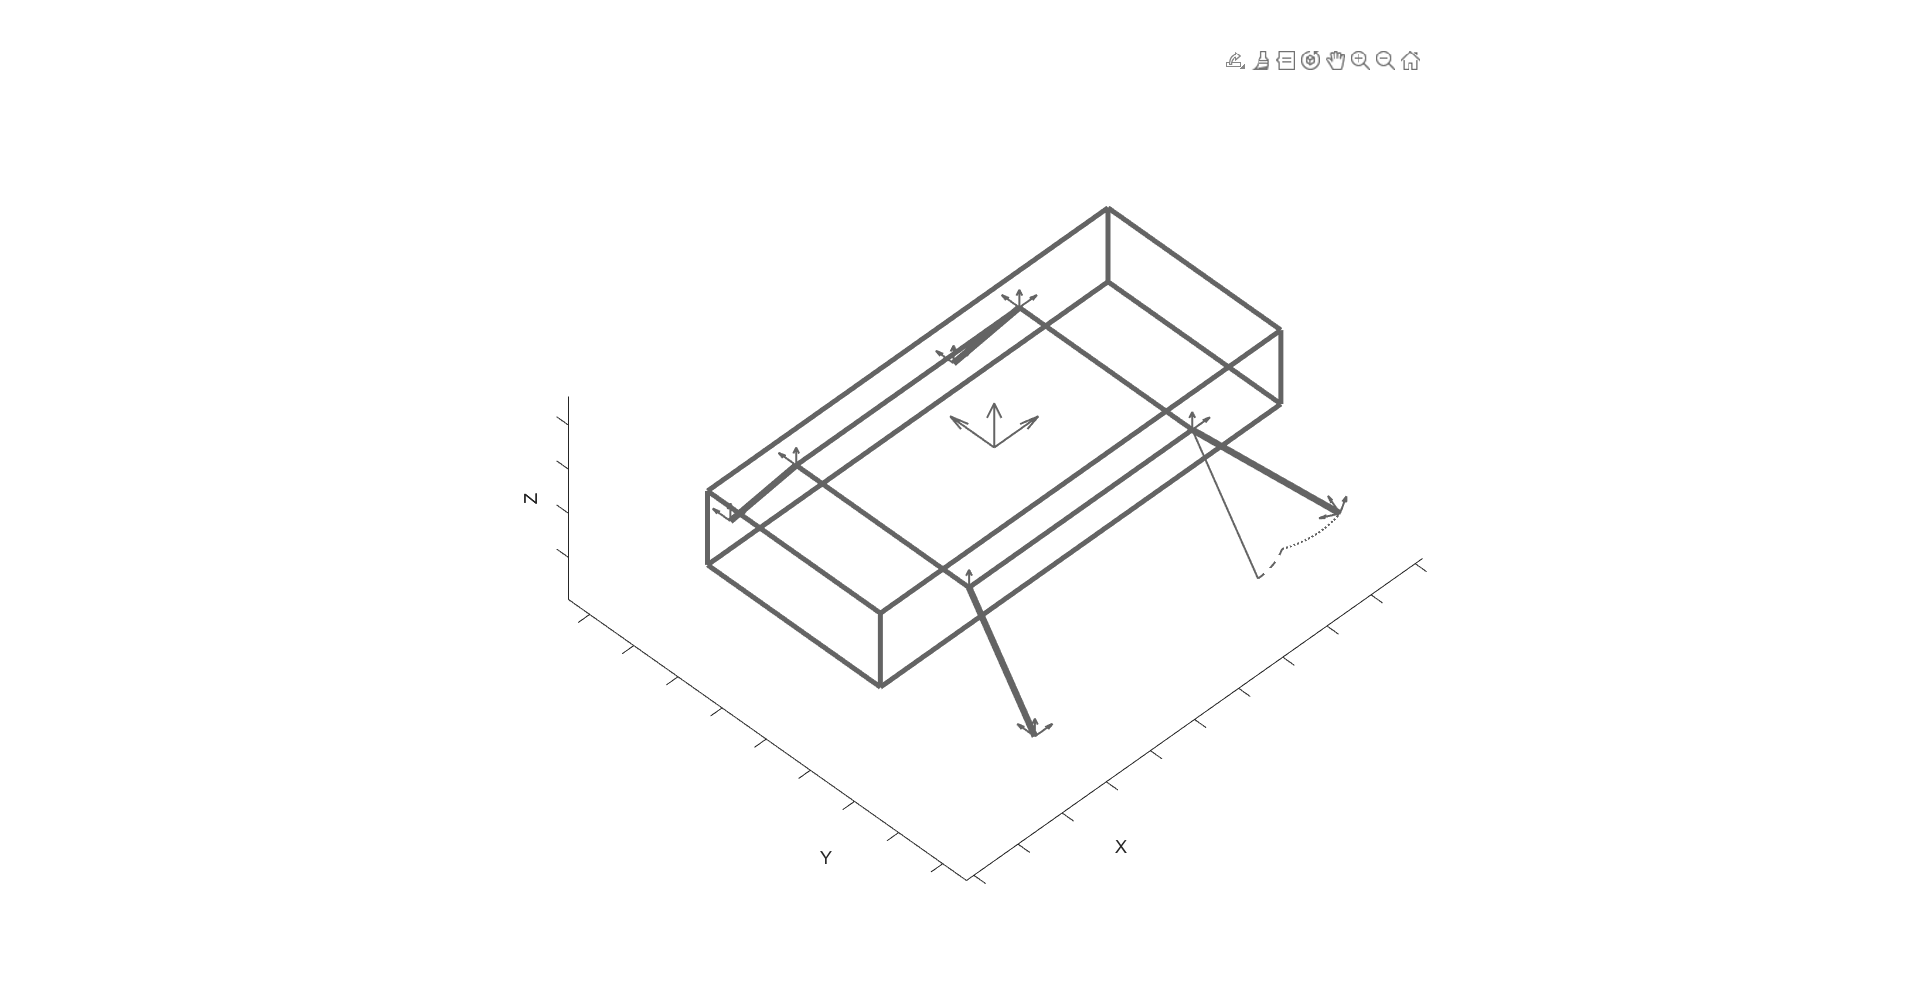

% add utilities function to the path and load data
addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');

% rename the structure
HAMR_6_SE3 = HAMR_6.SE3;

% Assuming symmetric limits in swing and lift for say 30 degs
mul = deg2rad(30);
r = num2cell(mul*[1, 1, zeros(1, 6)])';                 % FR leg swung and lifted by 30 degs
% r = num2cell(mul*[zeros(1, 2), 1, 1, zeros(1, 4)]);   % FL leg swung and lifted by 30 degs
% r = num2cell(mul*[zeros(1, 4), 1, 1, zeros(1, 2)]);   % RL leg swung and lifted by 30 degs
% r = num2cell(mul*[zeros(1, 6), 1, 1]);                % RR leg swung and lifted by 30 degs
% r = num2cell(2*mul*rand(1, 8) - mul);                 % random combination of lift and swing angles for all legs

% Let's say the body is coincident with the origin with 0
b = {0, 0, 0, 0, 0, 0}';

% Generate the SE3 locations
traj = computeSE3trajectory(r, b, HAMR_6_SE3);
traj.bl = HAMR_6_SE3.params.bl;

% Set the camera angle-- descriptions assume the system is in 0 roll, pitch, yaw
% v = [-135, +45];       % isometric LHS view
v = [-45, +45];        % isometric RHS view
% v = [-90, 90];         % Top View
% v = [90, -90];         % Bot View
% v = [-180, 0];         % Left View
% v = [0, 0];            % Right View
% v = [-9, 9];            % Right(-ish) View
% v = [90, 0];           % Front View
% v = [-90, 0];          % Back View

% plot the configuration
figure('units','pixels','position',[0 0 1920 1080],'Color','w');
set(gcf,'Visible','on'); % pop-out figure
plotSE3snapshot(gca, traj, v, []);

Next, we can proceed towards adding more functionality and animating the system.

### Animations of HAMR 6 Mocap Data

#### Find the right transformation between the R_map and RPY values in HAMR 6 dataset

% expidx = 30;
% tidx = 100;
% r = Metrics(expidx).Roll(tidx) + pi
% p = Metrics(expidx).Pitch(tidx)
% y = Metrics(expidx).Yaw(tidx)
% % Paper claims x, y, and z aligned with roll, pitch, and yaw-- let's do an xyz transformation then
% R_ours = R_SE3(rotx_SE3(r)*roty_SE3(p)*rotz_SE3(y))
% R_ours_m = eul2rotm([r, p, y], 'XYZ')
% R_truth = Metrics(expidx).R_map(:, :, 100)
% figure()
% quiver3(zeros(3,1), zeros(3,1), zeros(3,1), R_ours(:, 1), R_ours(:, 2), R_ours(:, 3), 'LineStyle', '--', 'LineWidth', 1.2, 'Color', 'r');
% hold on; axis equal square padded;
% quiver3(zeros(3,1), zeros(3,1), zeros(3,1), R_ours_m(:, 1), R_ours_m(:, 2), R_ours_m(:, 3), 'LineStyle', ':', 'LineWidth', 1.2, 'Color', 'r');
% quiver3(zeros(3,1), zeros(3,1), zeros(3,1), R_truth(:, 1), R_truth(:, 2), R_truth(:, 3), 'LineStyle', '-', 'LineWidth', 1.2, 'Color', 'k');

If we add $\pi$ to the roll vector, then the R_map given and what we generate match exactly-- however this is not needed for our 3D reconstruction, hence this section can be ignored.

Here, we can work on the 3D reconstruction of HAMR 6's actual trajectory to tease things out-- this is what we from this section. 

Let's iterate over all the experiments in 1 Hz trotting behaviours from each dataset-- manual way.

% % % % % % % % % addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');
% % % % % % % % % 
% % % % % % % % % % Define constants/transforms
% % % % % % % % % m2mm = 1e3; bl = HAMR_6_SE3.params.bl;
% % % % % % % % % 
% % % % % % % % % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % % % % % % % % % obtain the experiment of interest %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % % % % % % % % load('Data\HAMR6_Metrics_07-Sep-2016.mat');
% % % % % % % % % trot_exp_D2 = []; exp_num = []; f = [];
% % % % % % % % % for i = 1:numel(Metrics)
% % % % % % % % %     if string(Metrics(i).Gait) == 'Trot'
% % % % % % % % %         exp_num = [exp_num, i];
% % % % % % % % %         f = [f, Metrics(i).Frequency];
% % % % % % % % %     end
% % % % % % % % % end
% % % % % % % % % [c, ~, ic] = unique(f);
% % % % % % % % % trot_exp_D2.exp_num = {}; trot_exp_D2.f = {};
% % % % % % % % % for i = 1:numel(c)
% % % % % % % % %     trot_exp_D2.f{i} = c(i);
% % % % % % % % %     trot_exp_D2.exp_num{i} = exp_num( ic == i );
% % % % % % % % % end
% % % % % % % % % trot_exp_D2.f{1} % lowest frequency is 1Hz

ans = 1

% % % % % % % % % trot_exp_D2.exp_num{1}

ans =    147   184   293   310


% % % % % % % % % i_str = {'FR', 'FL', 'RL', 'RR'}; % correspondence between out leg frame naming and dataset

Here, let's iterate over this dataset and start collecting data

% % % % % % % % % for idx = 1:numel(trot_exp_D2.exp_num{1}) % also timing every run
% % % % % % % % %     trot = Metrics(trot_exp_D2.exp_num{1}(idx)); clear Metrics; % 1Hz Trot
% % % % % % % % %                                                                 % 1: trot w/ crawl
% % % % % % % % %                                                                 % 2: trot w/ crawl
% % % % % % % % %                                                                 % 3: trot
% % % % % % % % %                                                                 % 4: trot
% % % % % % % % %     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % % % % % % % % 
% % % % % % % % %     % Post-processing on experimental data-- contact and color information
% % % % % % % % %     b = {m2mm*trot.XYZCOM(1,:); m2mm*trot.XYZCOM(2,:); m2mm*trot.XYZCOM(3,:);... % body data is in meters-- convert2mm 
% % % % % % % % %         (trot.Roll(:))'; trot.Pitch(:)'; trot.Yaw(:)'};
% % % % % % % % %     ht3_e__i_exp = cell(4, 1); C_i_exp = ht3_e__i_exp; temp = [];
% % % % % % % % %     for j = 1:4
% % % % % % % % %         ht3_e__i_exp{j} = m2mm*trot.([i_str{j}, 'footXYZ']);    % foot location in rest frame
% % % % % % % % %         idx_c = ( ht3_e__i_exp{j}(3, :) < 0.01*bl );            % indices where the current foot is below the 1% of BL z-threshold        
% % % % % % % % %         C_i_exp{j} = idx_c;                                     % the indicies calculated earlier will determine the contact
% % % % % % % % %         ht3_e__i_exp{j}(3, idx_c) = 0;                          % zero-out the z-value at these indicies.
% % % % % % % % %         temp = [temp; abs(diff(C_i_exp{j}))];
% % % % % % % % %     end
% % % % % % % % %     delC_i_exp = (sum(temp, 1) > 0);
% % % % % % % % %     [S_exp, traj_col_exp] = compute_submanifold_color(C_i_exp, delC_i_exp, HAMR_6_SE3);
% % % % % % % % % 
% % % % % % % % %     % % % % % % % % % % % % % % % % % % UNCOMMENT BELOW IF SHAPES ARE NEEDED FOR A NEW EXPERIMENT (runs for 2mins)
% % % % % % % % %     % estimate the shape trajectories
% % % % % % % % %     r_trot = apprxSFBswingliftSE3(b, ht3_e__i_exp, HAMR_6_SE3);
% % % % % % % % % 
% % % % % % % % %     % compute body/3D reconstruction trajectory
% % % % % % % % %     t = trot.Time;
% % % % % % % % %     r = vecSE3traj(r_trot);
% % % % % % % % %     traj_est = computeSE3trajectory(r, b, HAMR_6_SE3);
% % % % % % % % %     traj_est.exp.t = t;
% % % % % % % % %     traj_est.exp.tnum = numel(trot.Time);
% % % % % % % % %     traj_est.exp.ht3_e__i = ht3_e__i_exp;
% % % % % % % % %     traj_est.exp.C_i = C_i_exp;
% % % % % % % % %     traj_est.exp.delC_i = delC_i_exp;
% % % % % % % % %     traj_est.exp.S = S_exp;
% % % % % % % % %     traj_est.exp.col = traj_col_exp;
% % % % % % % % %     traj_est.bl = HAMR_6_SE3.params.bl;
% % % % % % % % % 
% % % % % % % % %     % Append this to the trot_exp structure
% % % % % % % % %     trot_exp_D2.traj{1}{idx} = traj_est;
% % % % % % % % % end

Elapsed time is 221.777583 seconds.


% % % % % % % % % % Create sub-structures to save the estimated data
% % % % % % % % % HAMR_6.D2.trot = trot_exp_D2;
% % % % % % % % % 
% % % % % % % % % % Save the trot experimental and estimated trajectory information strcuture to "HAMR_6.mat"
% % % % % % % % % save('Data\HAMR6_SE3_kinematics.mat', 'HAMR_6');

Automated way of iterating over experiments-- sweeps all trotting frequencies in the second dataset. RUNS FOR 8 HOURS WITH GPU SUPPORT!

% % % % addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');
% % % % str_2 = 'Data\HAMR6_Metrics_07-Sep-2016.mat';
% % % % trot_exp_D2 = estHAMRtraj(str_2, HAMR_6.SE3);
% % % % HAMR_6.D2.trot = trot_exp_D2;

Now, we shall do the same for the first dataset.

% % % % str_1 = 'Data\20160515_HAMR.mat'; trot_exp_D1 = estHAMRtraj(str_1, HAMR_6.SE3);
% % % % HAMR_6.D1.trot = trot_exp_D1;
% % % % save('Data\HAMR6_SE3_kinematics.mat', 'HAMR_6');

We have all the data we need! Let's try animating some of these systems!

Here, we animate the data from dataset 2!

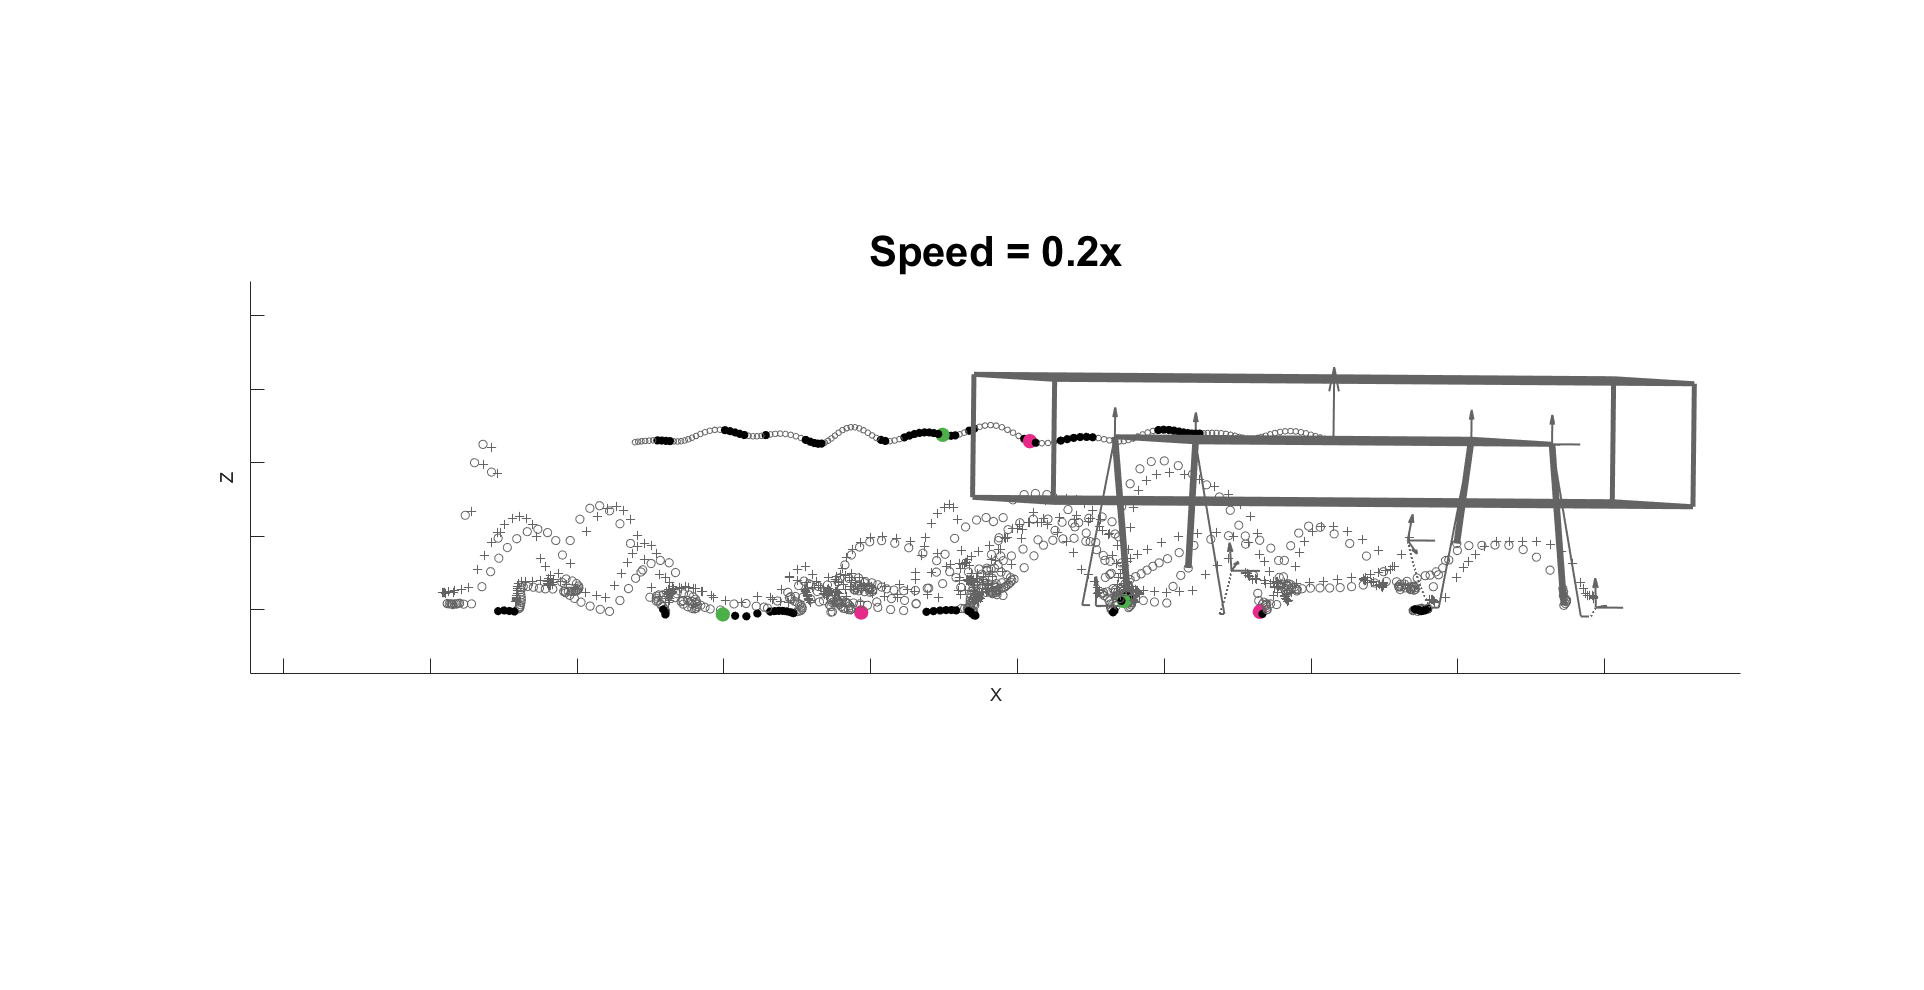

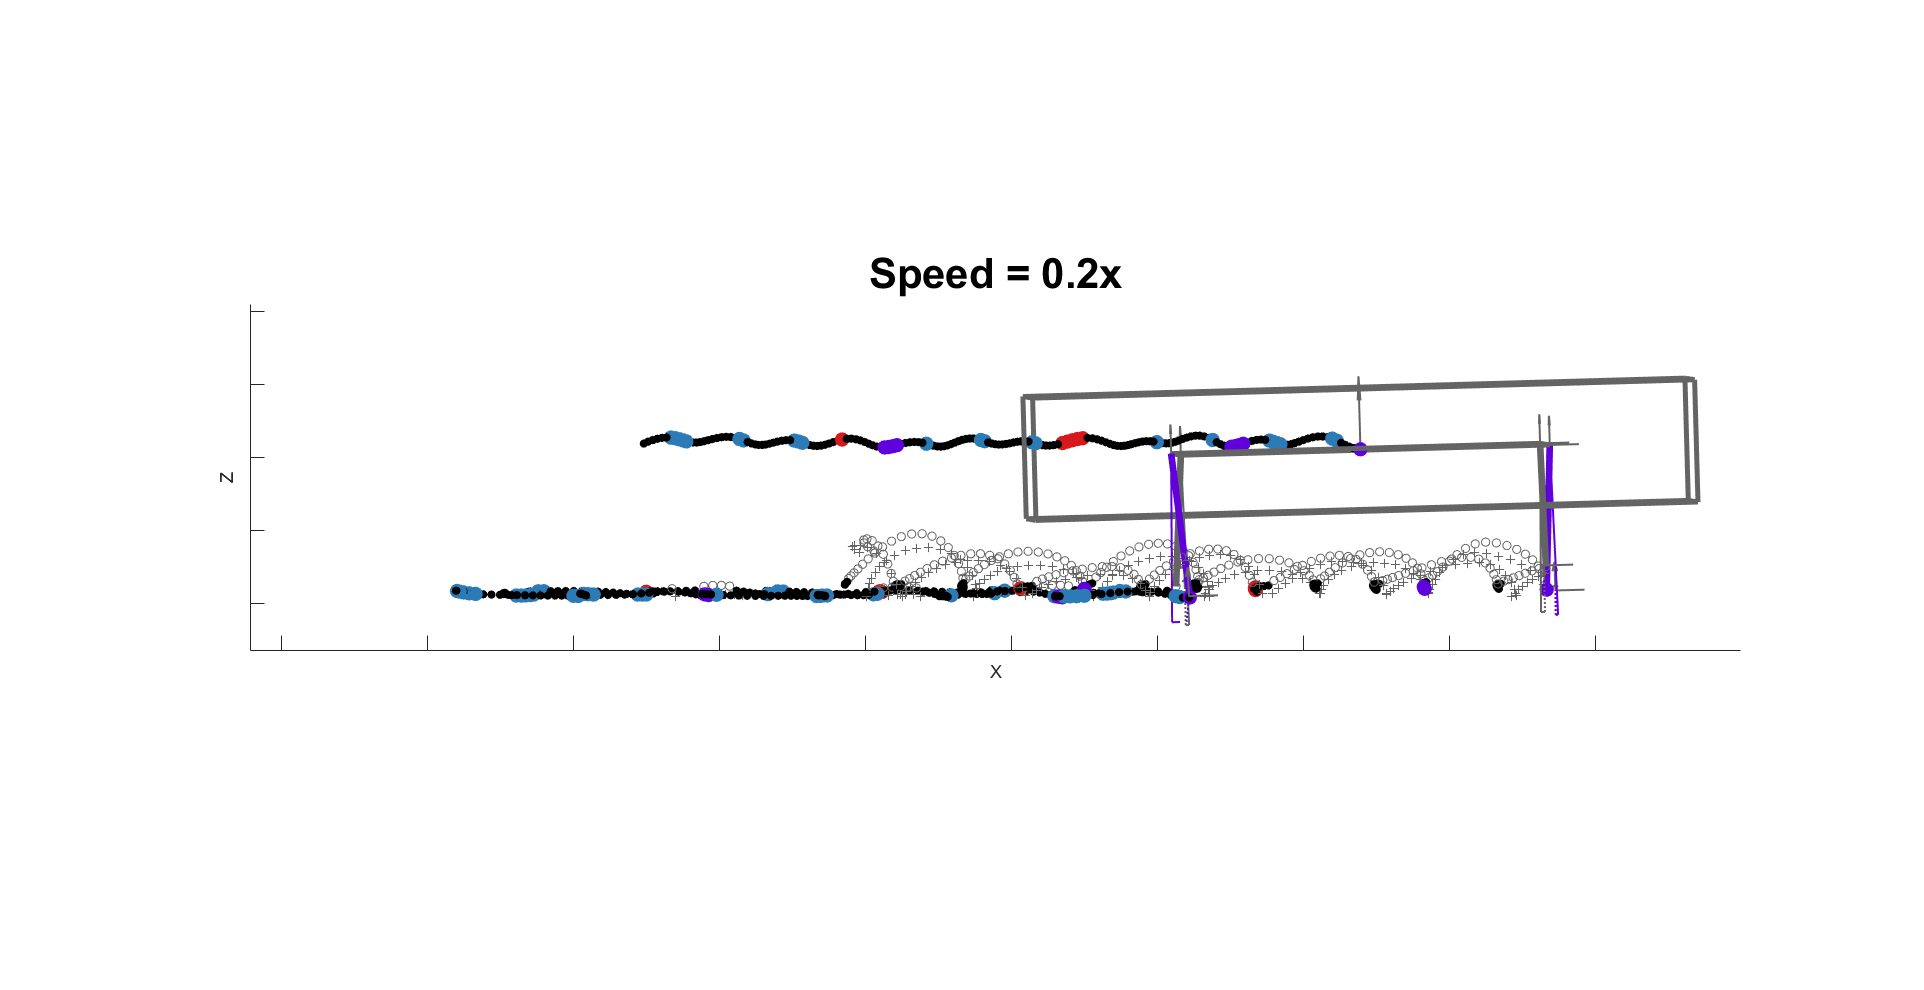

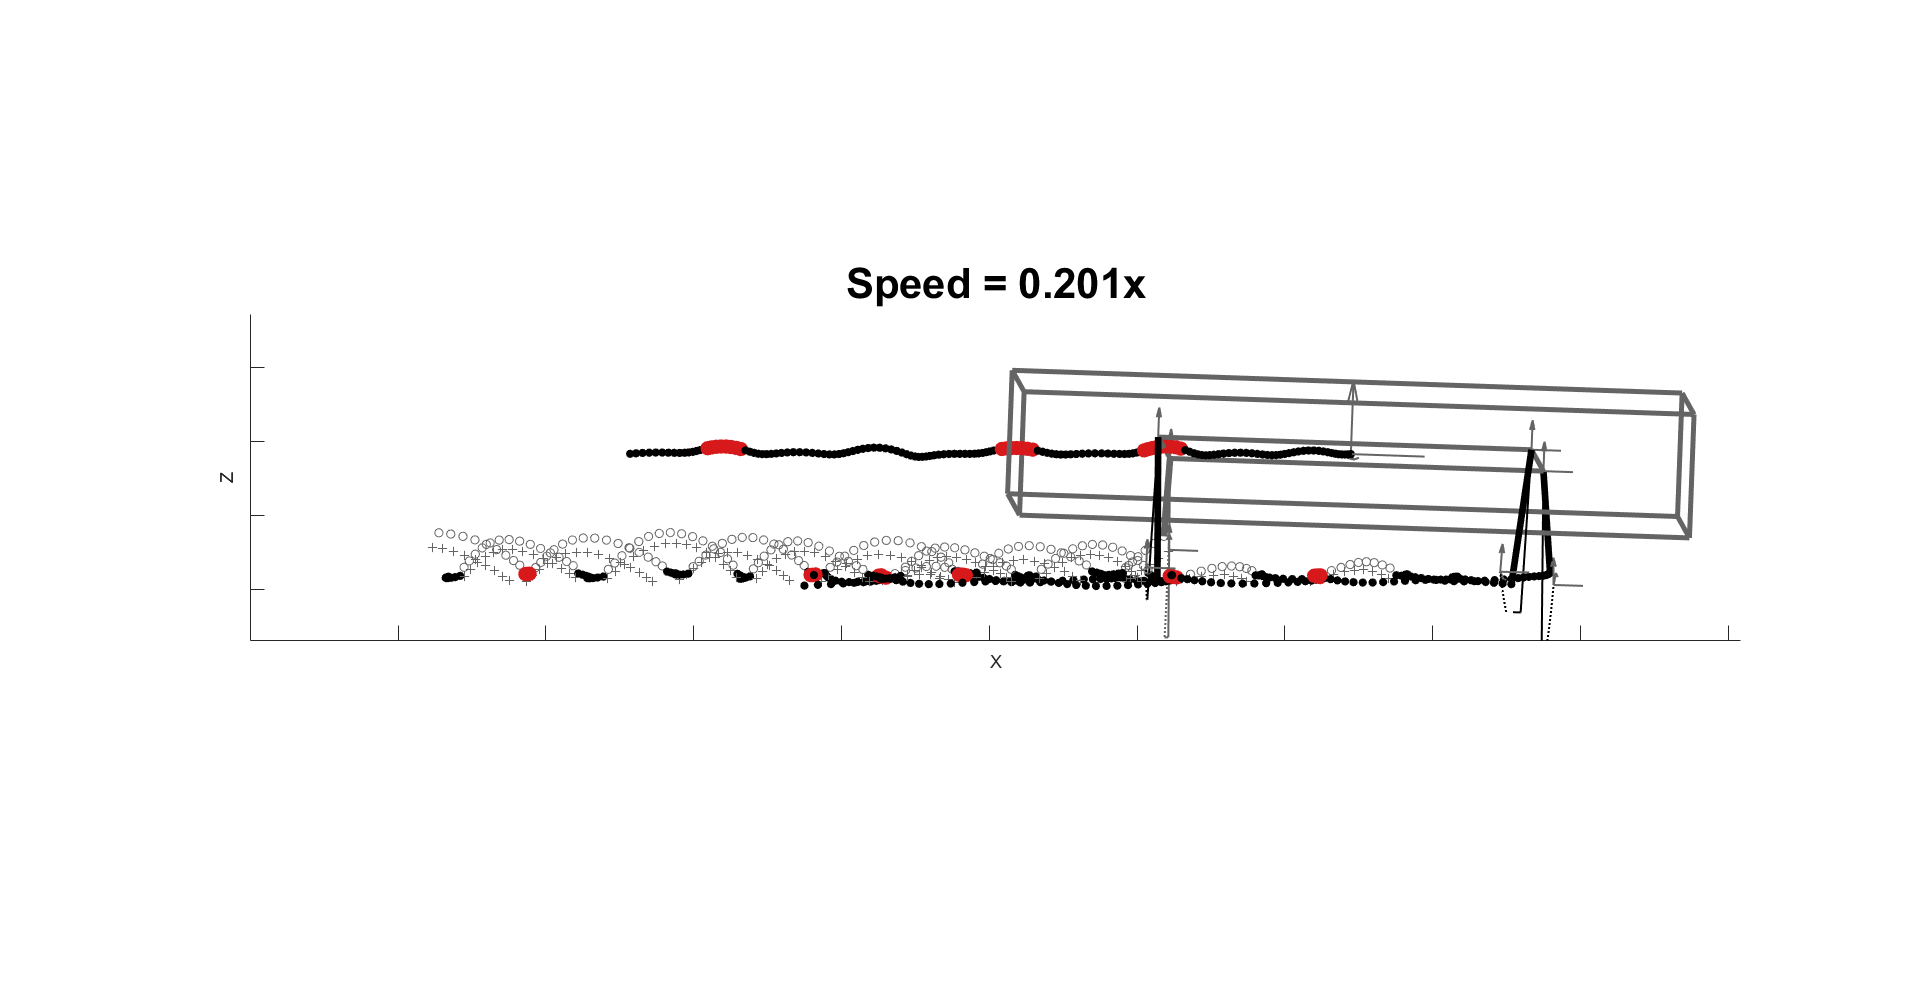

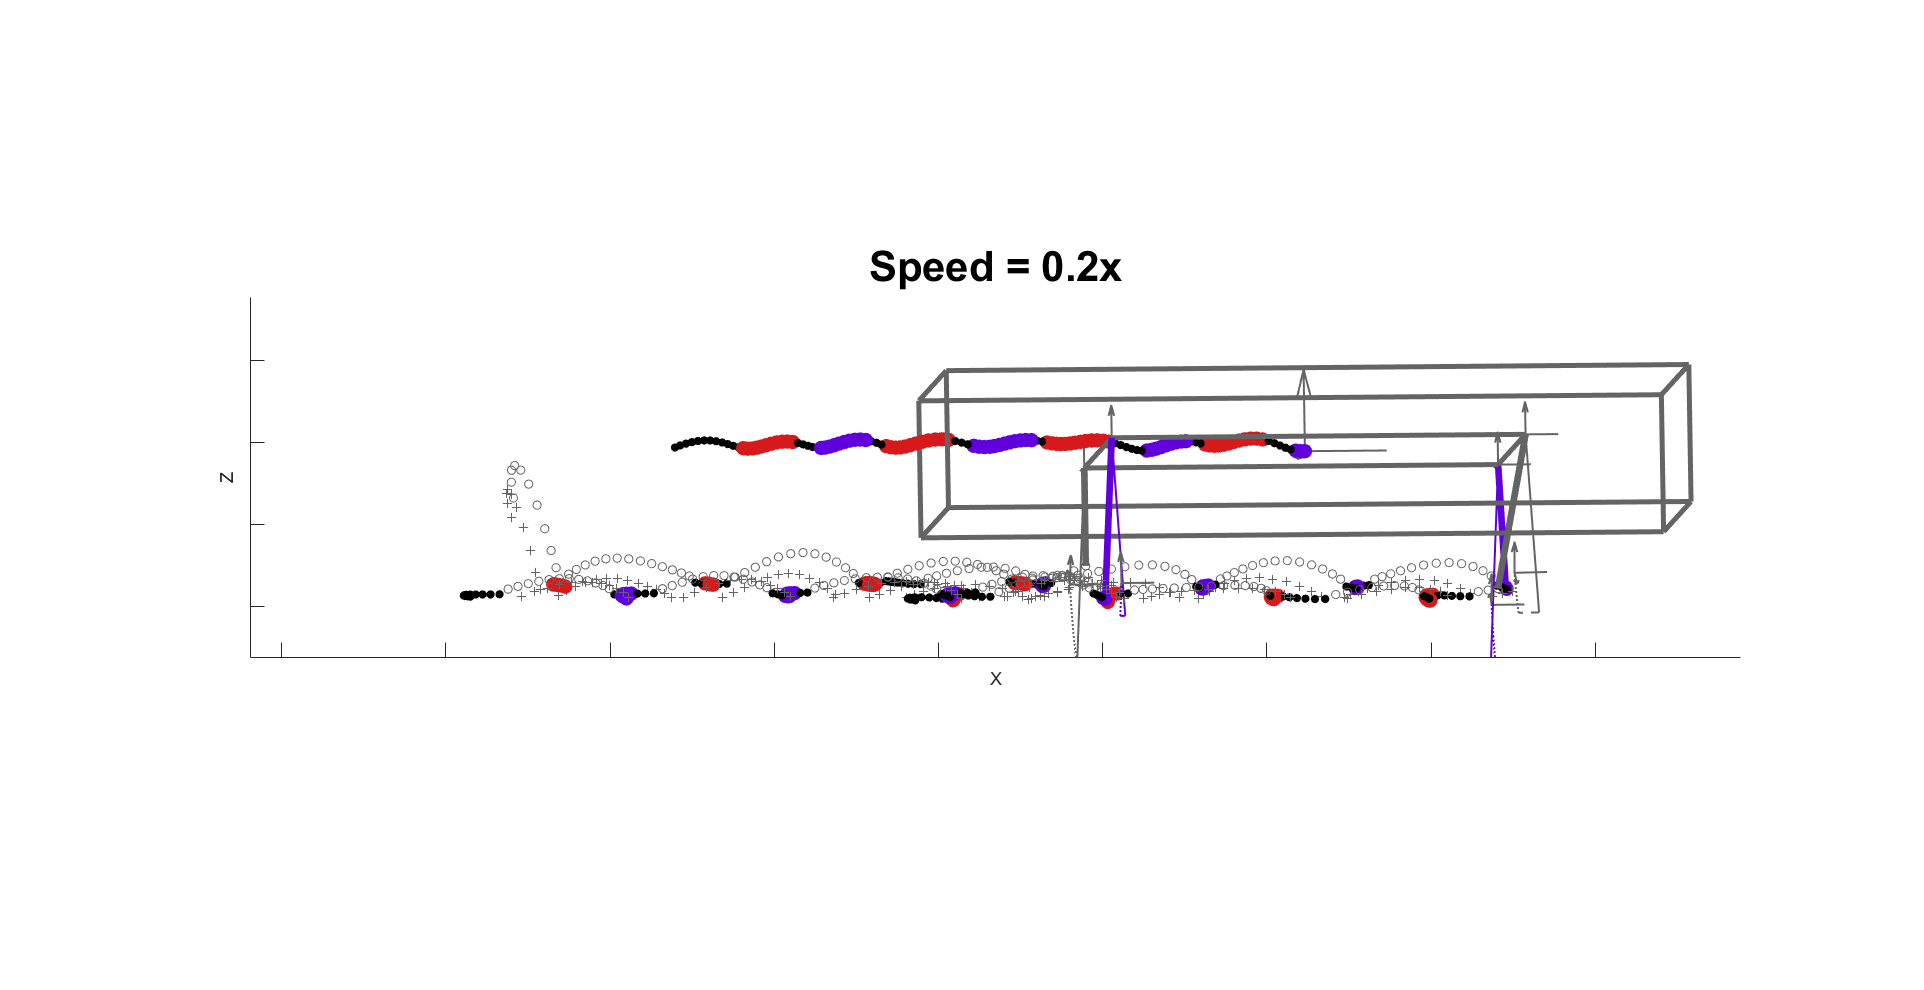

addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');
% select an experiment
expn = 4;
% idx = numel(HAMR_6.D2.trot.exp_num{expn});
for idx = 1%:numel(HAMR_6.D2.trot.exp_num{expn}) %%%%% UNCOMMENT HERE TO TRY ALL CASES
    % Extract the relevant data
    trot = HAMR_6.D2.trot.traj{expn}{idx};
    
    % video and camera parameters (uncomment name and view together)
    v = [];
    v.FrameRate = floor( (trot.exp.tnum - 1)/(trot.exp.t(end) - trot.exp.t(1)) );
    if v.FrameRate > 60
        v.Speed = round(60/v.FrameRate, 3);
        v.FrameRate = 60;
    end
    v.Quality = 100;
    % v.Name = ['D2_Trot_' num2str(HAMR_6.D2.trot.f{expn}) 'Hz_Exp', num2str(idx), '_isoRHSview'];
    % v.View = [-45, +15];                            % isometric RHS view %%%%% CAMERA LINE OF SIGHT (camlos)
    v.Name = ['D2_Trot_' num2str(HAMR_6.D2.trot.f{expn}) 'Hz_Exp', num2str(idx), '_RHS_SagittalView'];
    v.View = [0, 0];                            % RHS Sagittal View
    v.VidF = true;
    
    % animate
    animateSE3sys(trot, v);
end

% v.Name = ['D2_Trot_' num2str(HAMR_6.D2.trot.f{expn}) 'Hz_Exp', num2str(idx), '_Topview'];
% v.View = [-90, 90];                           % Top View
% animateSE3sys(trot, v);

Plotting COM z-data of an arbitrary experiment.

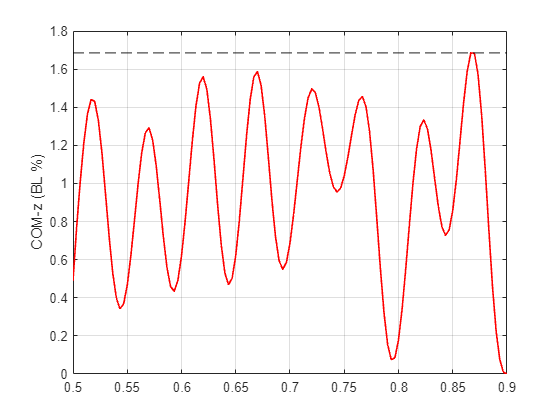

% addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');
bl = HAMR_6.SE3.params.bl; % bl
expn = 4; % 10Hz
idx = numel(HAMR_6.D2.trot.exp_num{expn}); % last run
tCOMz_norm = vecSE3traj(p_SE3(HAMR_6.D2.trot.traj{expn}{idx}.tH3_e__b)); tCOMz_norm = 100*(tCOMz_norm{3} - min(tCOMz_norm{3}))/bl;
t = HAMR_6.D2.trot.traj{expn}{idx}.exp.t;
figure()
plot(gca, t, tCOMz_norm, 'r', 'LineWidth', 1.2); grid on; hold on;
yline(gca, max(tCOMz_norm), 'k--', 'LineWidth', 1.0); ylabel('COM-z (BL %)'); % [min(tCOMz_norm) max(tCOMz_norm)]

Here, we animate the data from dataset 1!

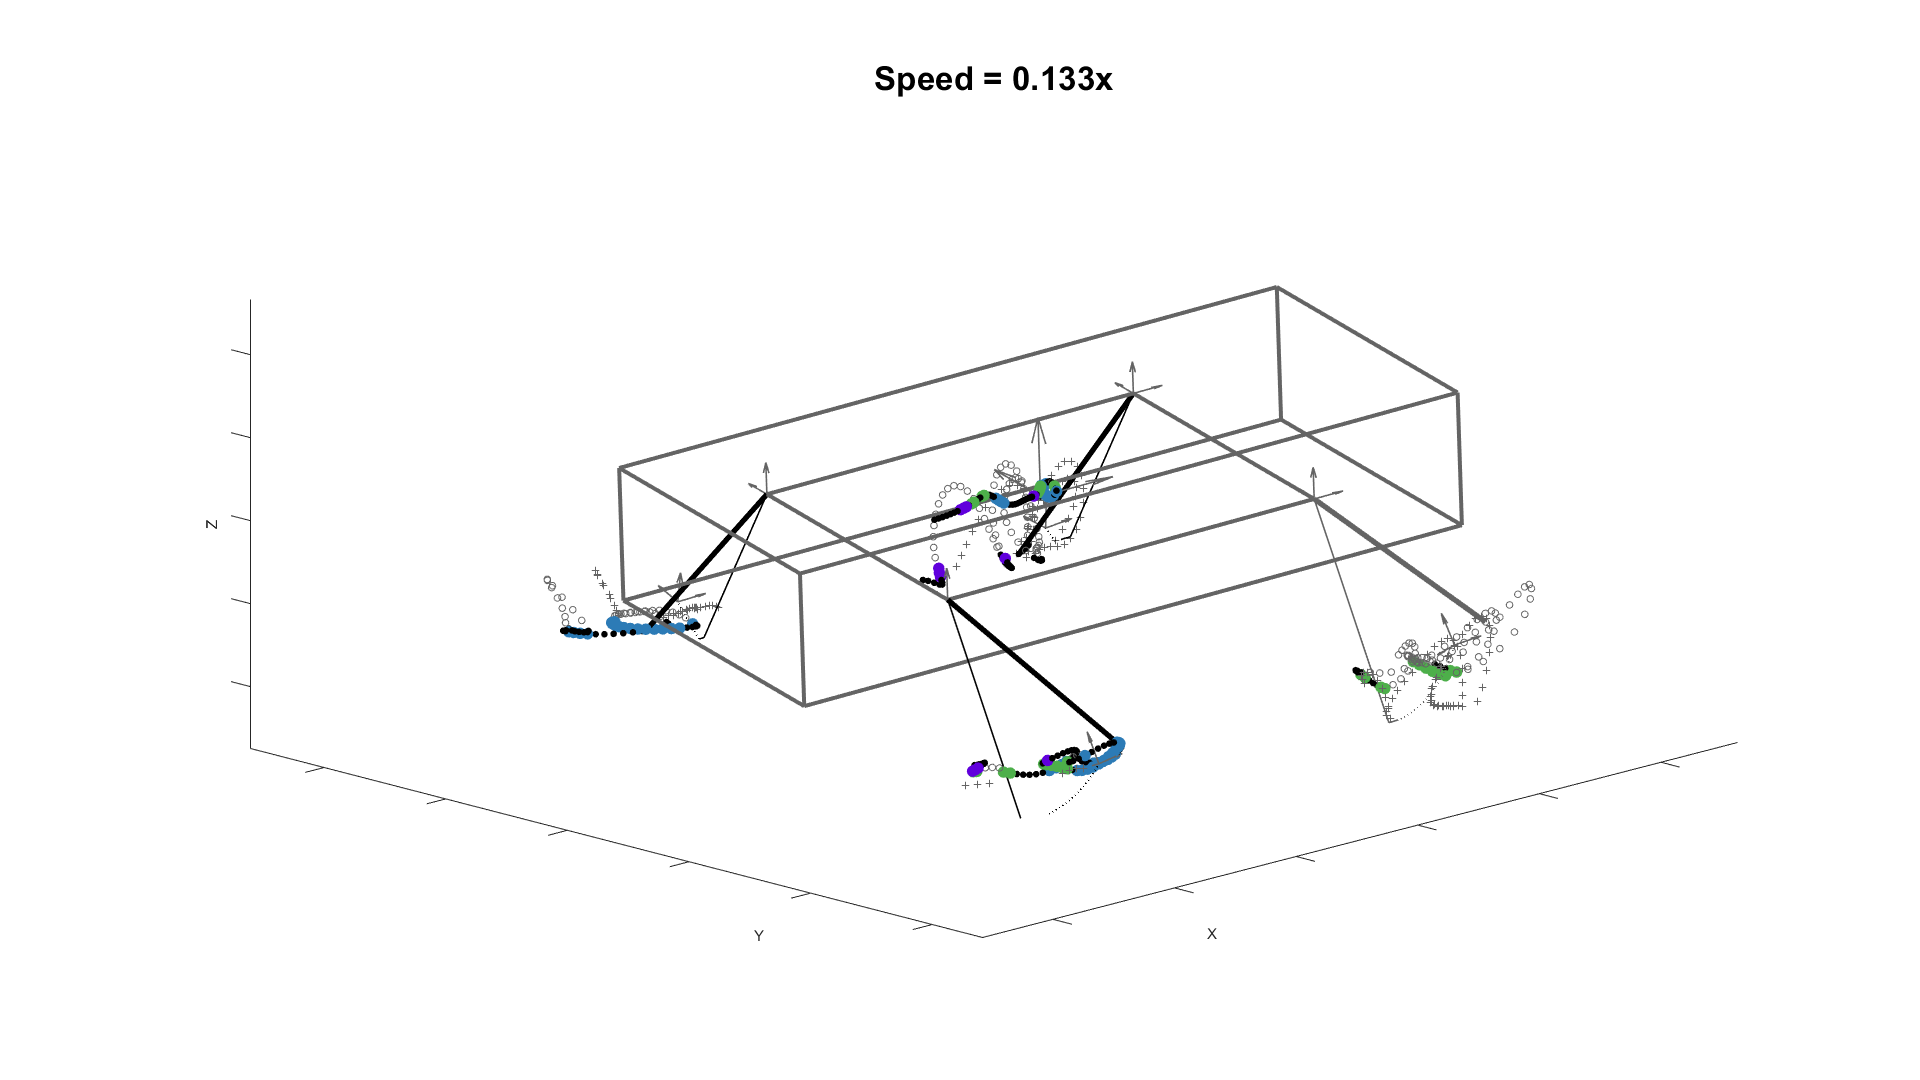

% % % % % addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');
expn = 5; % numel(HAMR_6.D1.trot.f) % 1
% idx = 2; % 2
for idx = 1:numel(HAMR_6.D1.trot.exp_num{expn})

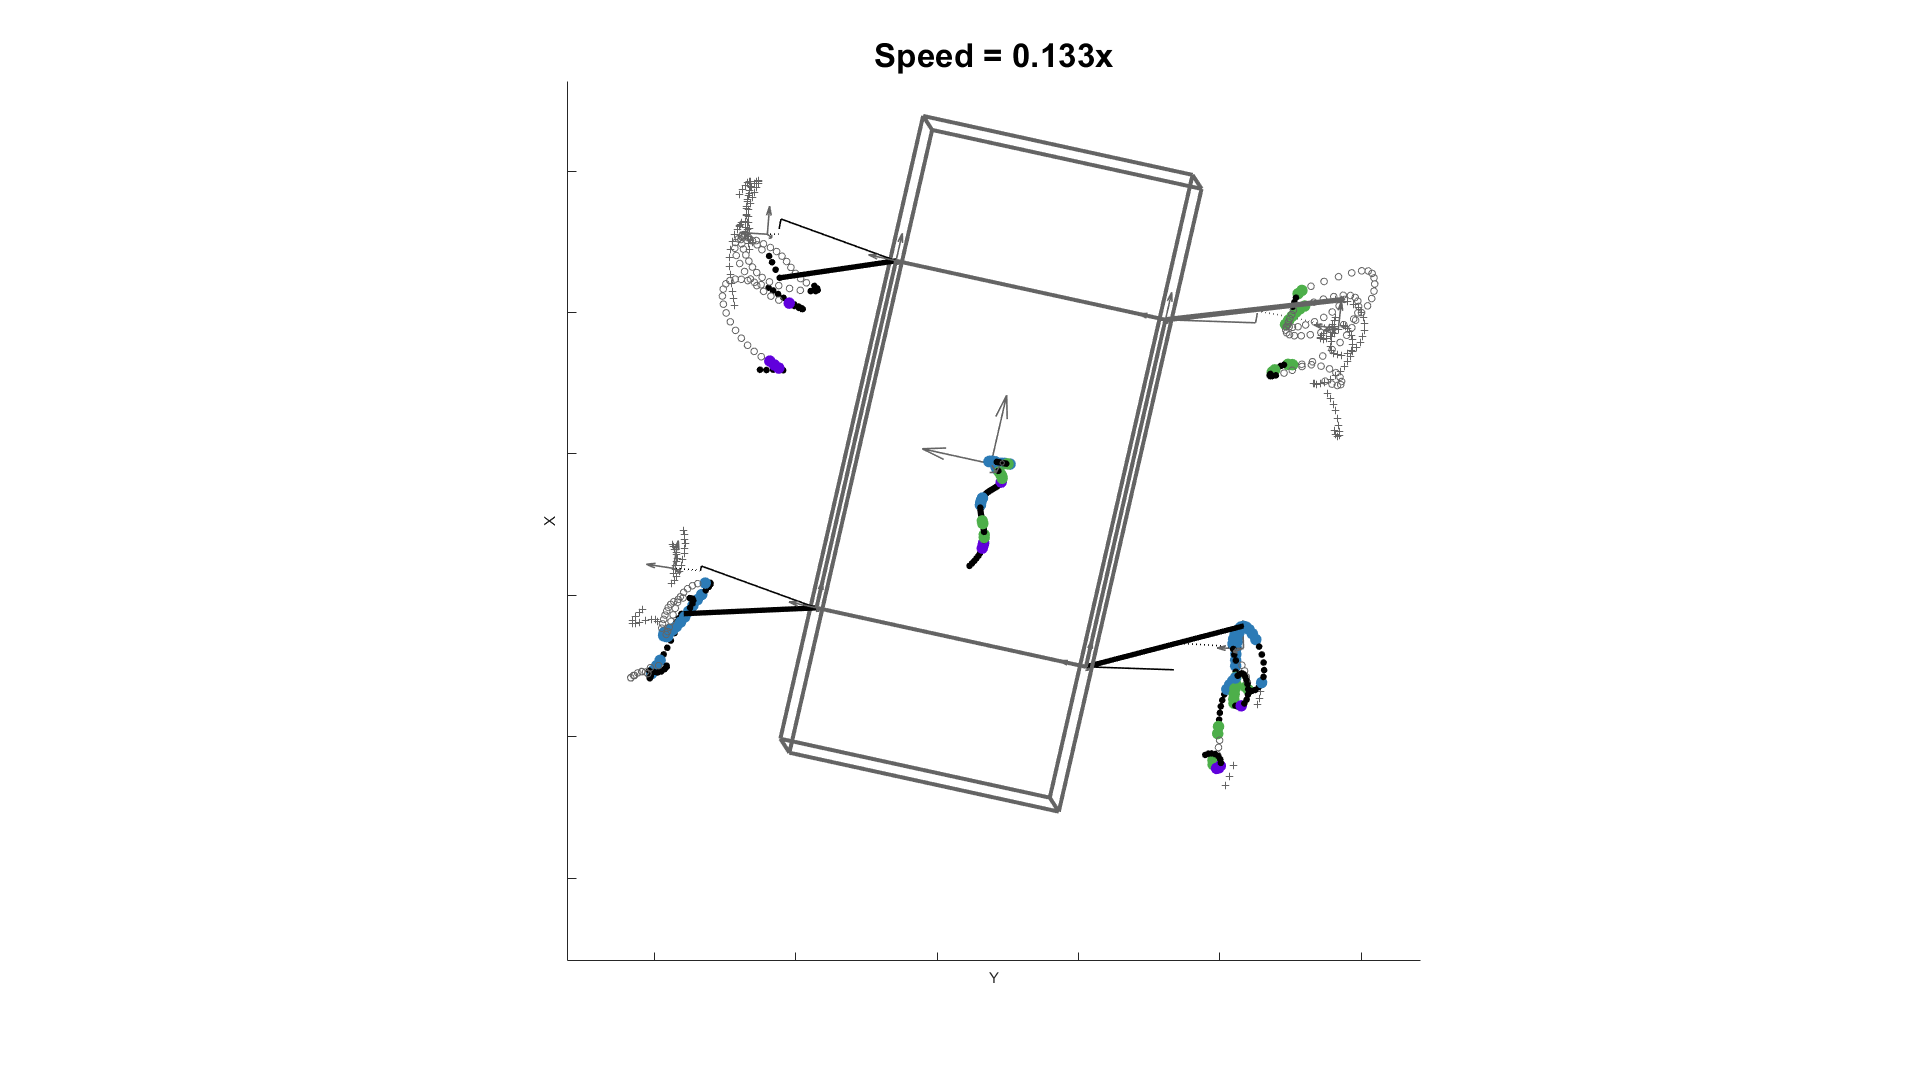

    trot = HAMR_6.D1.trot.traj{expn}{idx};
    if exist('v', 'var')
        clear v;
    end
    v.FrameRate = floor( (trot.exp.tnum - 1)/(trot.exp.t(end) - trot.exp.t(1)) );
    if v.FrameRate > 60
        v.Speed = round(60/v.FrameRate, 3);
        v.FrameRate = 60;
    end
    v.Quality = 100;
    % v.Name = ['D1_Trot_' num2str(HAMR_6.D1.trot.f{expn}) 'Hz_Exp', num2str(idx), '_isoRHSview'];
    % v.View = [-45, +15];                            % isometric RHS view %%%%% CAMERA LINE OF SIGHT (camlos)
    v.Name = ['D1_Trot_' num2str(HAMR_6.D1.trot.f{expn}) 'Hz_Exp', num2str(idx), '_RHS_SagittalView'];
    v.View = [0, 0];                            % RHS Sagittal View
    v.VidF = true;
    animateSE3sys(trot, v);
end
% v.Name = ['D1_Trot_' num2str(HAMR_6.D1.trot.f{expn}) 'Hz_Exp', num2str(idx), '_Topview'];
% v.View = [-90, 90];                           % Top View
% animateSE3sys(trot, v);

% % % % addpath 'Data'\ 'Utility Functions'\; load('Data\HAMR6_SE3_kinematics.mat');
% % % syms x y z a b c real
% % % H3_b__i = HAMR_6.SE3.transforms.sym.H3_b__i;
% % % for i = 1:numel(H3_b__i)
% % %     eval(['syms alpha_' num2str(i) ' beta_' num2str(i) ' real']); % add assumptions to symbols involved before computing
% % % end
% % % H3_e__b =  HAMR_6.SE3.transforms.sym.H3_e__b; H3_ib__i = HAMR_6.SE3.transforms.sym.H3_ib__i;
% % % H2_e__b = simplify(fromSE3toSE2frames(H3_e__b), 'Steps', 10);
% % % H2_b__i = fromSE3toSE2frames(H3_b__i); 
% % % H2_ib__i = fromSE3toSE2frames(H3_ib__i); % collapse frames
% % % for i = 1:numel(H2_b__i)
% % %     H2_b__i{i} = simplify(H2_b__i{i}, 'Steps', 10);
% % % end
% % % for i = 1:numel(H2_ib__i)
% % %     H2_ib__i{i} = simplify(H2_ib__i{i}, 'Steps', 10);
% % % end
% % % J2_b__i = adj_adjinv_SE2(H2_b__i, -1);
% % % for i = 1:numel(J2_b__i)
% % %     J2_b__i{i} = simplify(J2_b__i{i}, 'Steps', 10);
% % % end
% % % J2_ib__i = adj_adjinv_SE2(H2_ib__i, -1);
% % % for i = 1:numel(J2_ib__i)
% % %     J2_ib__i{i} = simplify(J2_ib__i{i}(:, 3), 'Steps', 10);
% % % end
% % % J2_i = computefulljacobianSE2(J2_b__i, J2_ib__i, 4);
% % % fH2_e__b = matlabFunction(H2_e__b, 'Vars', HAMR_6.SE3.config.B);
% % % fH2_b__i = cell(size(H2_b__i)); fH2_ib__i = cell(size(H2_ib__i)); 
% % % fJ2_b__i = cell(size(J2_b__i)); fJ2_ib__i = cell(size(J2_ib__i)); fJ2_i = cell(size(J2_i));
% % % for i = 1:numel(H2_b__i)
% % %     fH2_b__i{i} = matlabFunction(H2_b__i, 'Vars', HAMR_6.SE3.config.R);
% % % end
% % % for i = 1:numel(H2_ib__i)
% % %     fH2_ib__i{i} = matlabFunction(H2_ib__i, 'Vars', HAMR_6.SE3.config.R);
% % % end
% % % for i = 1:numel(J2_b__i)
% % %     fJ2_b__i{i} = matlabFunction(J2_b__i, 'Vars', HAMR_6.SE3.config.R);
% % % end
% % % for i = 1:numel(J2_ib__i)
% % %     fJ2_ib__i{i} = matlabFunction(J2_ib__i, 'Vars', HAMR_6.SE3.config.R);
% % % end
% % % for i = 1:numel(J2_i)
% % %     fJ2_i{i} = matlabFunction(J2_i, 'Vars', HAMR_6.SE3.config.R);
% % % end
% % % HAMR_6.SE2 = []; % "_proj" is added to all stored variables to distinguish true SE(2) transforms without roll and pitch (done later) from the projected ones
% % % % symbolic transforms -- 2D projection
% % % HAMR_6.SE2.transforms.sym.H2_e__b_proj = H2_e__b; % body to foot
% % % HAMR_6.SE2.transforms.sym.H2_b__i_proj = H2_b__i; % body to foot
% % % HAMR_6.SE2.transforms.sym.H2_ib__i_proj = H2_ib__i; % hip to foot
% % % HAMR_6.SE2.transforms.sym.J2_b__i_proj = J2_b__i; % jacobian from body to feet
% % % HAMR_6.SE2.transforms.sym.J2_ib__i_proj = J2_ib__i; % jacobian from hip to feet
% % % HAMR_6.SE2.transforms.sym.J2_i_proj = J2_i; % full jacobian from body and hip to the feet
% % % % functional transforms -- 2D projection
% % % HAMR_6.SE2.transforms.fun.fH2_e__b_proj = fH2_e__b; % body to foot
% % % HAMR_6.SE2.transforms.fun.fH2_b__i_proj = fH2_b__i; % body to foot
% % % HAMR_6.SE2.transforms.fun.fH2_ib__i_proj = fH2_ib__i; % hip to foot
% % % HAMR_6.SE2.transforms.fun.fJ2_b__i_proj = fJ2_b__i; % jacobian from body to feet
% % % HAMR_6.SE2.transforms.fun.fJ2_ib__i_proj = fJ2_ib__i; % jacobian from hip to feet
% % % HAMR_6.SE2.transforms.fun.fJ2_i_proj = fJ2_i; % full jacobian from body and hip to the feet
% % % H2_e__b = HAMR_6.SE2.transforms.sym.H2_e__b_proj;
% % % TeLg_proj = R_SE2(H2_e__b);
% % % HAMR_6.SE2.transforms.sym.TeLg_proj = TeLg_proj;
% % % fTeLg_proj = matlabFunction(TeLg_proj, 'Vars', HAMR_6.SE3.config.B);
% % % HAMR_6.SE2.transforms.fun.fTeLg_proj = fTeLg_proj;
% % % H2_ib__i = HAMR_6.SE2.transforms.sym.H2_ib__i_proj; % hip to foot transforms
% % % alpha_proj = cell(size(H2_ib__i)); falpha_proj = alpha_proj; % initialize
% % % for i = 1:numel(H2_ib__i)
% % %     alpha_proj{i} = simplify(  atan(H2_ib__i{i}(2, 1)/H2_ib__i{i}(1, 1))  , 'IgnoreAnalyticConstraints', true); % compute projected swing angle
% % %     falpha_proj{i} = matlabFunction(alpha_proj{i}, 'Vars', HAMR_6.SE3.config.R);
% % % end
% % % HAMR_6.SE2.transforms.sym.alpha_proj = alpha_proj;
% % % HAMR_6.SE2.transforms.fun.falpha_proj = falpha_proj;
% % % % save('Data\HAMR6_SE3_kinematics.mat', 'HAMR_6', '-append');

## SE(2) Locomotion Kinematics

The SE(2) locomotion kinematics for HAMR's measurements are evaluated in "case_1_kinematics.mat"

### Estimating the body trajectory

Since, we have the full jacobians from the legs, we can now estimate the body velocity from shape trajectory.

%%%%% SETUP
% addpath 'Data'\ 'Utility Functions'\; 
% load('Data\HAMR6_SE3_kinematics.mat'); load('Data\HAMR6_SE2_kinematics.mat');
%%%%%% FOR PAPER-- 1Hz Run 3 ==> expn = 1; idx = 3;
expn = 1; % 1Hz
idx = 2; % run number
J = {J_1, J_2, J_3, J_4}';

%%%%% CHOOSE DATASET
flag = false;
switch flag
    case 0 % D1
        dataset_str = 'D1';
    case 1 % D2
        dataset_str = 'D2';
end

trot_f = HAMR_6.(dataset_str).trot.f;
trot = HAMR_6.(dataset_str).trot.traj{expn}{idx}; % get the desired experimental run
trot.exp.f = trot_f{expn};

%%%%% COMPUTE PRELIMINARIES
trot.exp.r_dot = compute_fwddiff(trot.exp.t, trot.exp.r); % get the desired experimental run

%%%%% ESTIMATE TRAJECTORY
warning('off');
b0 = Path2.estimate_SE2_trajectory( trot, {J, hamr_a, hamr_l, 0.01*bl} ); % input cell array 4th entry:, 0.01*bl , 0.015*bl -- set the lower threshold for contact state re-estimation here
warning('on');

%%%%% FILENAMES
save_addr = ['G:\.shortcut-targets-by-id\1JaJT5KHfBB4CF0noalA83zWRaVP4z_MQ\HarikrishnaHariprasad' ...
    '\PhD\Projects\Collaborations\CLARI_modeling\Geometric CLARI Modeling\quadrupedlevel2noslip\202305_data' ...
    '\HAMR_SE2_Kinematics\Fitted Trajectory\']; % change this to the address to your save path
save_name = [dataset_str '_Trot_' num2str(trot_f{expn}) 'Hz_Run' num2str(idx) '_bdot_ct'];

Let's compare the estimated result to the actual trajectory taken by the system-- as timeseries, in the phase space, and in SE(2).

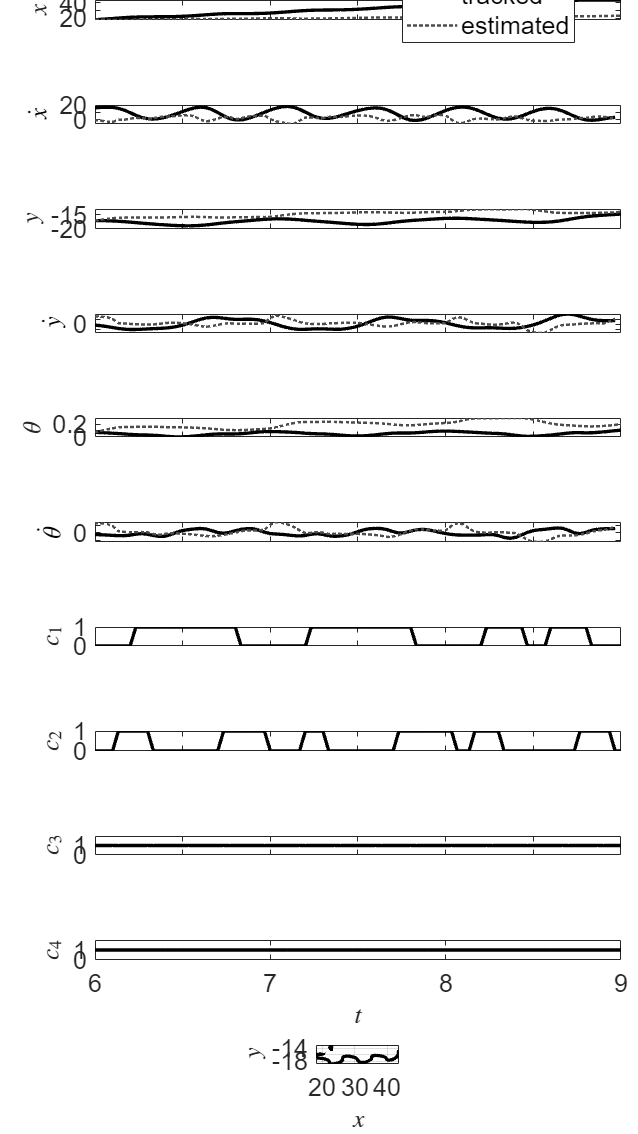

f = plotSE2timeseriestrajectory_bc(trot, b0);

% % UNCOMMENT BELOW TO SAVE THE FIGURES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% exportgraphics(f, [save_addr save_name '.png'], 'Resolution', 600, 'Colorspace', 'gray');
% saveas(f,  [save_addr save_name], 'svg');
% exportgraphics(f, [save_addr save_name '.pdf'], 'Resolution', 600, 'ContentType', 'vector', 'Colorspace', 'gray');
% savefig(f, [save_addr save_name '.fig'], 'compact');

For the HL leg (3rd), there seems to be a dip in the contact state ($c_3$) and let's get some snapshots around this point.

% camlos = [-135, 0];                                     % diagonal LHS view
% iters = find(trot.exp.t > 6.30 & trot.exp.t < 6.60);    % get the iters where we need the snapshot
% for k = 1:numel(iters)
%     f = figure('units','pixels','position',[0 0 1920 1080],'Color','w');
%     plotSE3snapshot(gca, trot, camlos, iters(k));
%     % exportgraphics(f, [save_addr 'debug_' num2str(k) '.png'], 'Resolution', 600); % , 'ContentType', 'vector', 'Colorspace', 'gray'
%     saveas(f,  [save_addr save_name], 'svg');
% end

Now, let's first compute the system's trajectory in the plotting format.

trot_SE2_est = computeSE2trajectory(trot.exp.r(1:2:end), b0, HAMR_6.SE2); % just the swing trajectory and ESTIMATED body trajectory
trot_SE2_est.bl = bl; % add the body length data
trot_SE2_est.exp = [];
trot_SE2_est.exp.col = trot.exp.col; trot_SE2_est.exp.C_i = trot.exp.C_i; % add some more stuff to the structure for animation
trot_SE2_est.exp.t = trot.exp.t;
trot_SE2_est.exp.tnum = trot.exp.tnum;

Let's use this plotting format to animate the SE(2) no-slip approximated trajectory of the system. ~~~~~~~~~~~~~ SKIP IF ANIMATION NOT NEEDED!

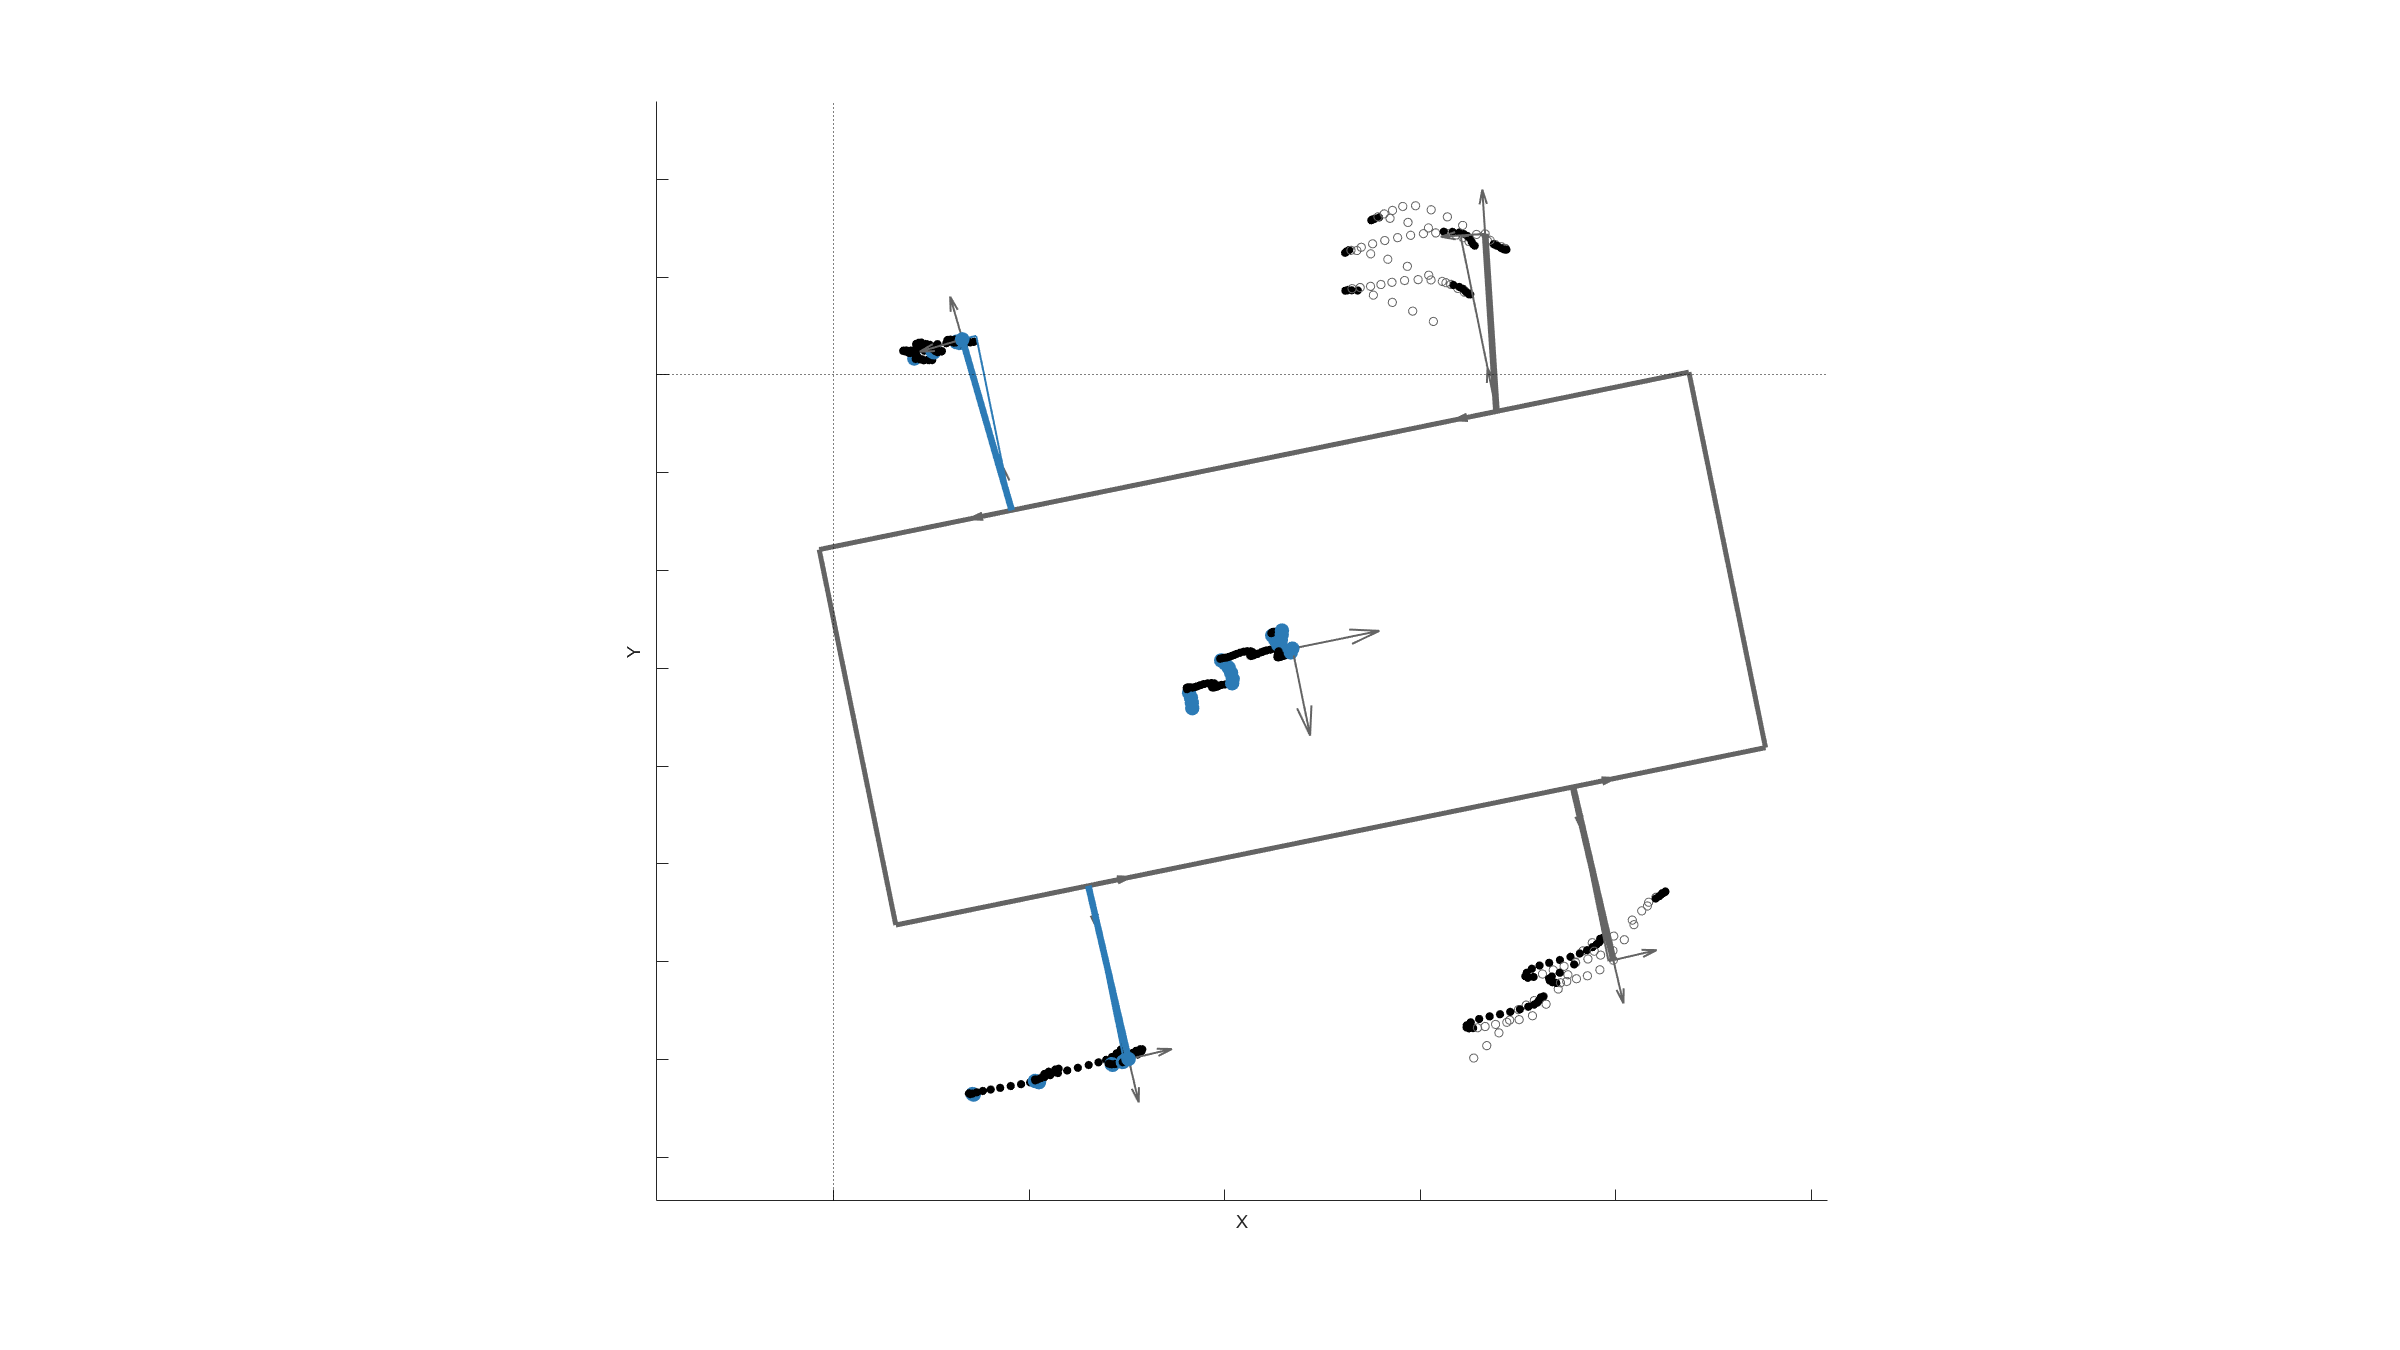

v = [];
v.FrameRate = floor( (trot_SE2_est.exp.tnum - 1)/(trot_SE2_est.exp.t(end) - trot_SE2_est.exp.t(1)) );
if v.FrameRate > 60
    v.Speed = round(60/v.FrameRate, 3);
    v.FrameRate = 60;
end
v.Quality = 100;
save_name = [dataset_str '_Trot_' num2str(trot_f{expn}) 'Hz_Run' num2str(idx) '__comp_H1'];
v.Name = [save_addr save_name];
v.VidF = true; % -------------------- % unset this if you don't want a video
animateSE2sys(trot_SE2_est, v);

Let's identify the peaks and approximate the swing timeseries as pure sinusoids.

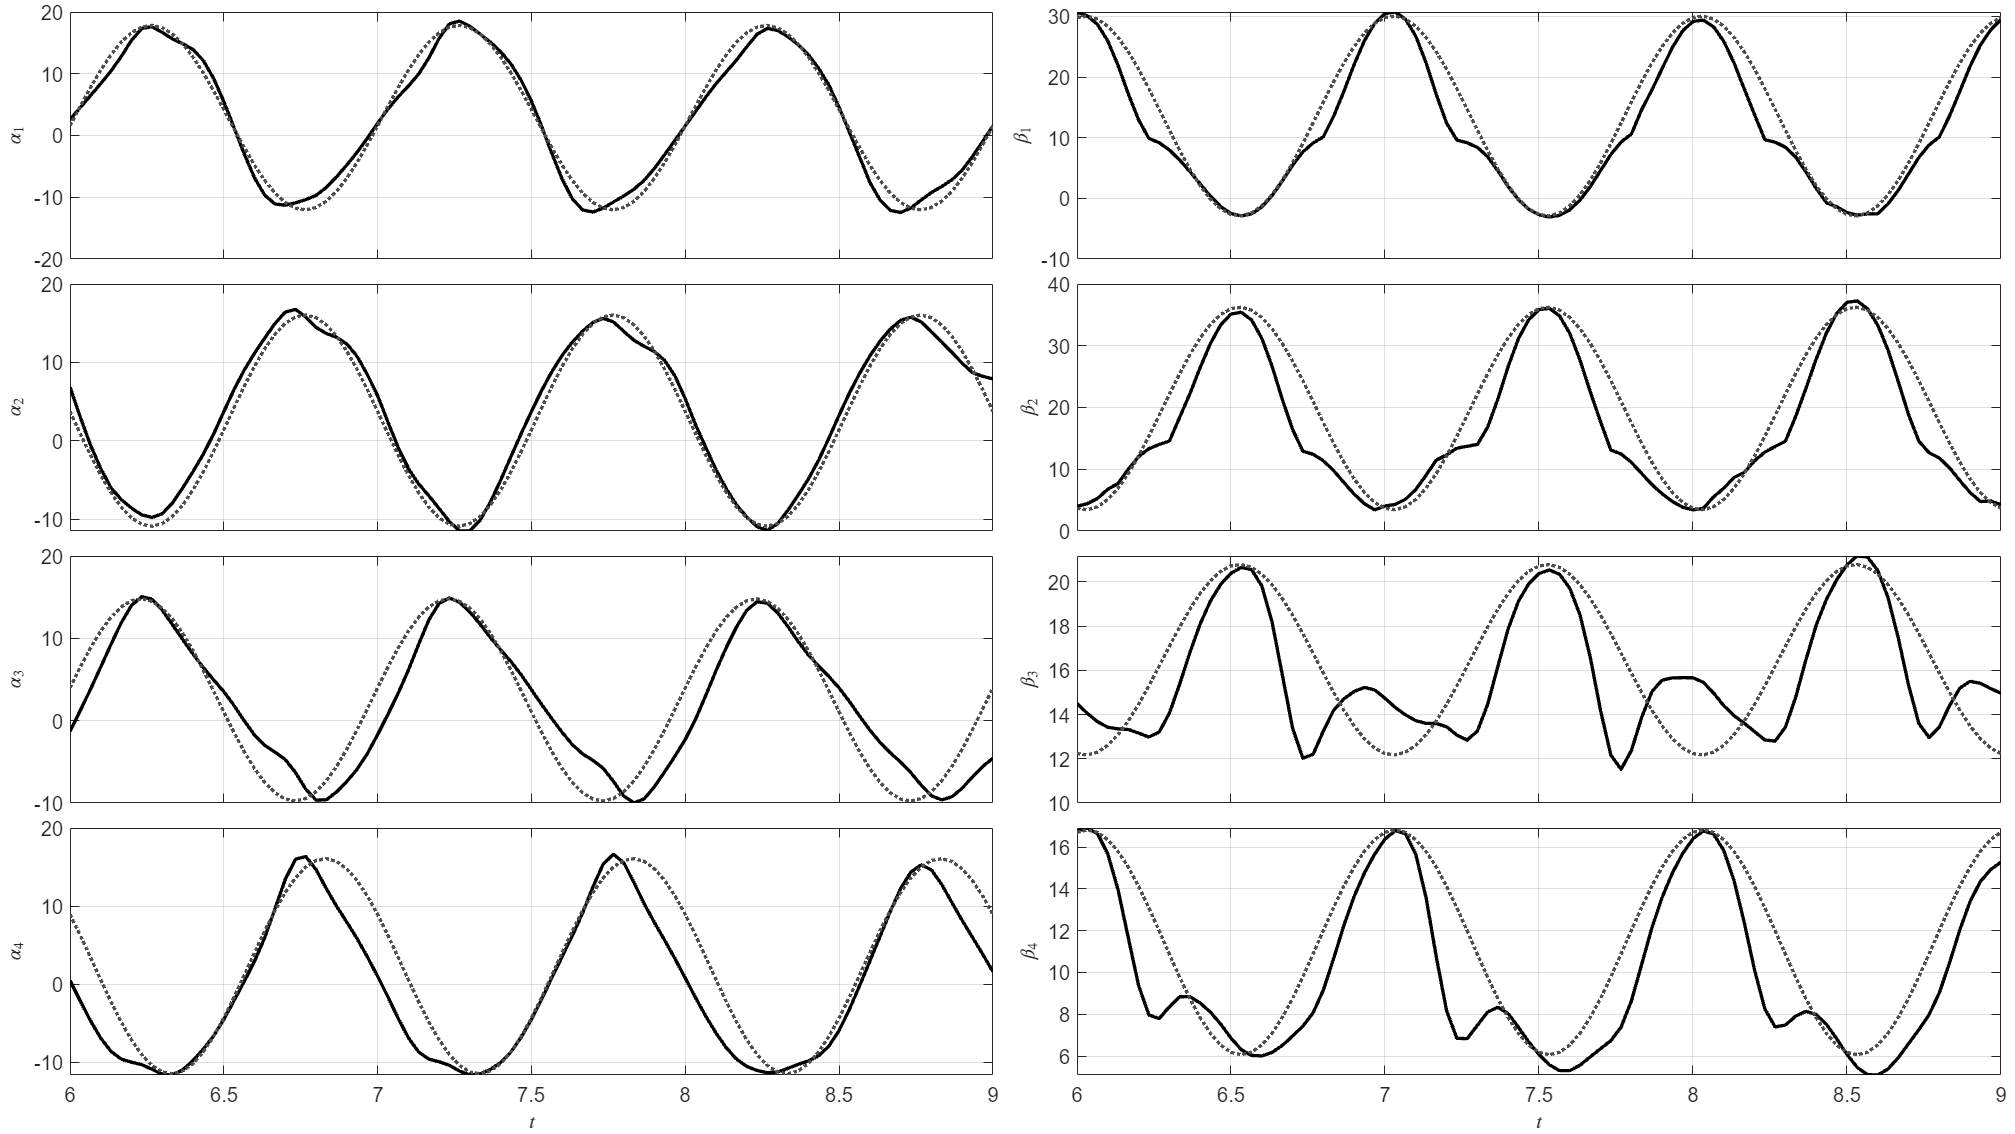

r_est = apprxsineswing(trot);
save_name = [dataset_str '_Trot_' num2str(trot_f{expn}) 'Hz_Run' num2str(idx) '_swing_lift_timeseries'];
f = plotSE2timeseriestrajectory_r(trot, true, r_est);
exportgraphics(f, [save_addr save_name '.png'], 'Resolution', 600, 'Colorspace', 'gray');
saveas(f,  [save_addr save_name], 'svg');
exportgraphics(f, [save_addr save_name '.pdf'], 'Resolution', 600, 'ContentType', 'vector', 'Colorspace', 'gray');

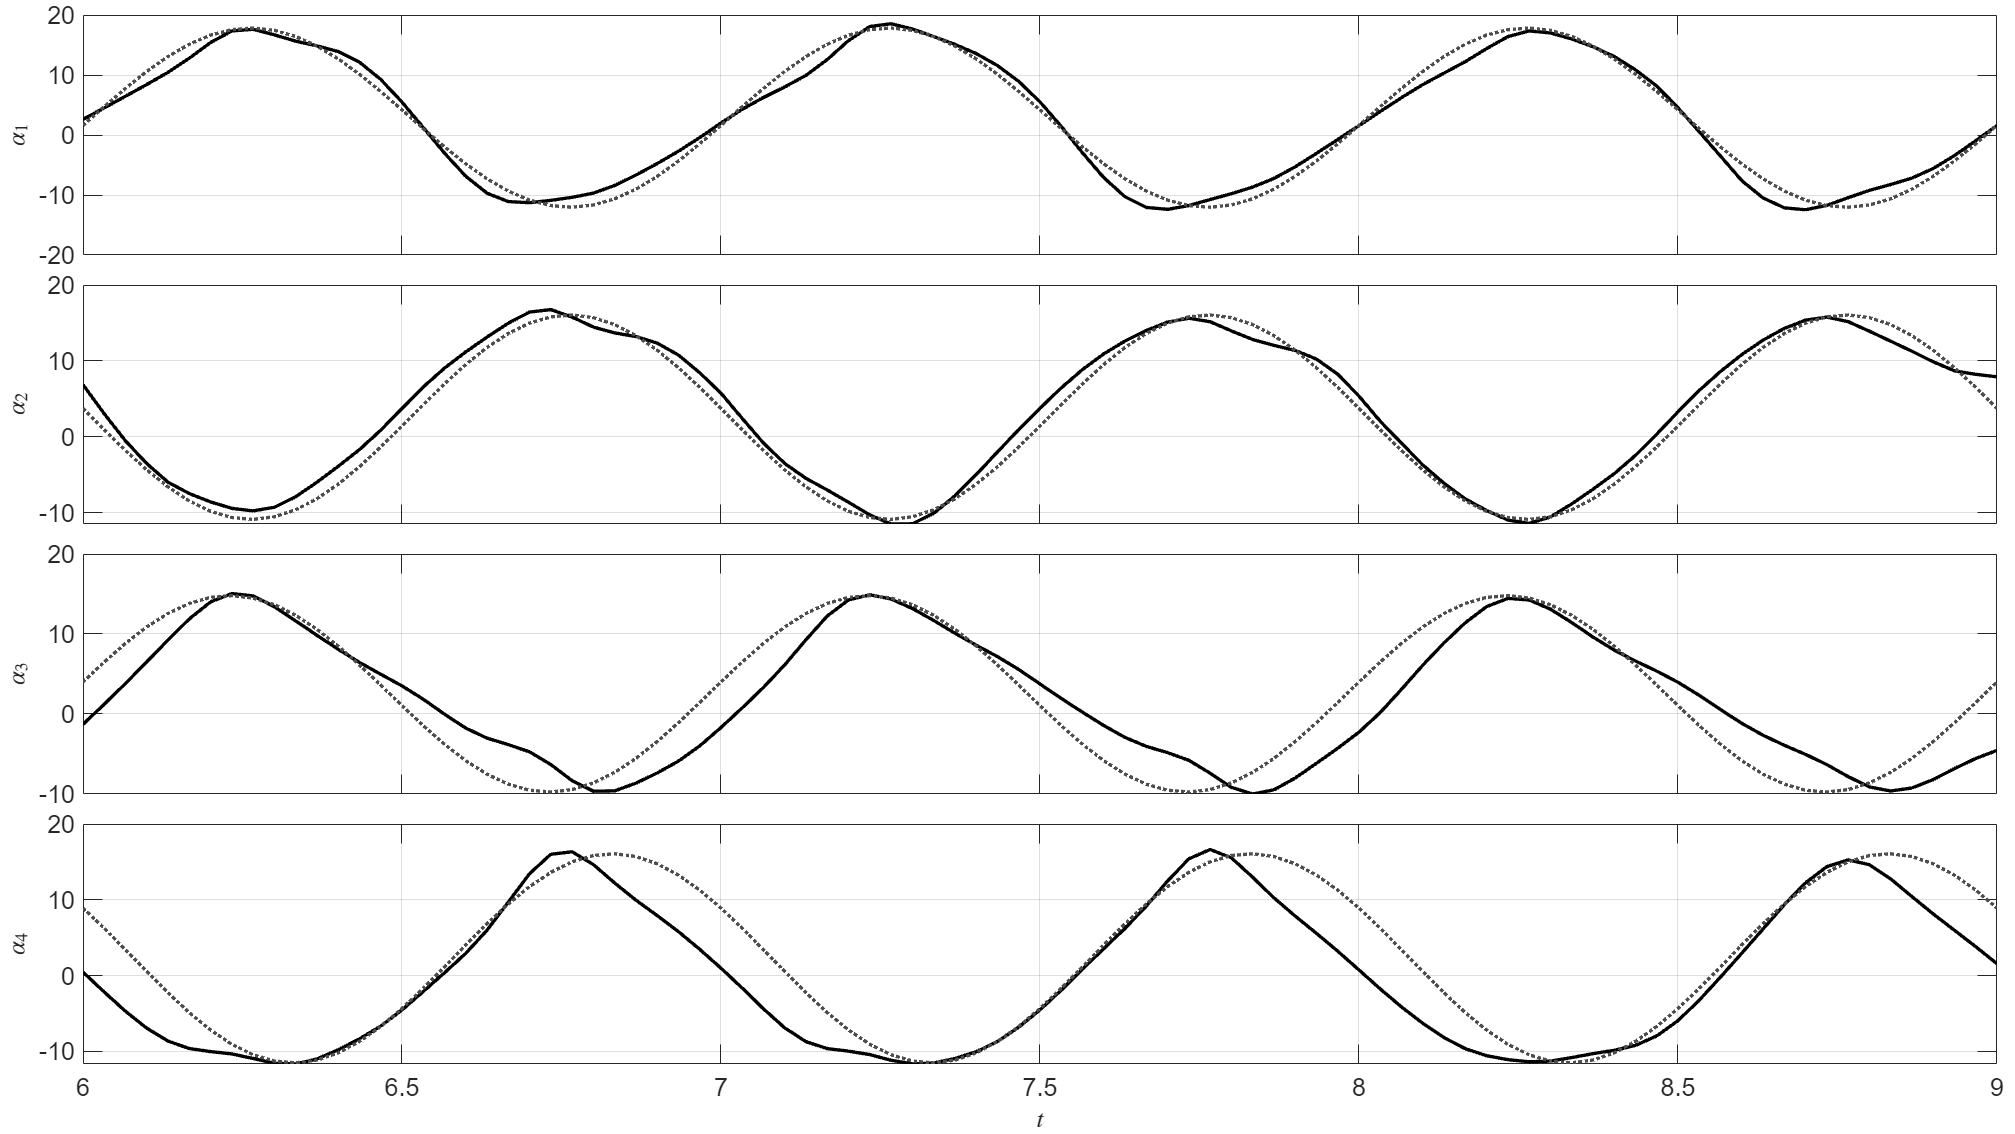

savefig(f, [save_addr save_name '.fig'], 'compact');
save_name = [dataset_str '_Trot_' num2str(trot_f{expn}) 'Hz_Run' num2str(idx) '_swing_timeseries'];
f = plotSE2timeseriestrajectory_r(trot, false, r_est);
exportgraphics(f, [save_addr save_name '.png'], 'Resolution', 600, 'Colorspace', 'gray');
saveas(f,  [save_addr save_name], 'svg');
exportgraphics(f, [save_addr save_name '.pdf'], 'Resolution', 600, 'ContentType', 'vector', 'Colorspace', 'gray');

savefig(f, [save_addr save_name '.fig'], 'compact');

Let's now pack the estimated trajectories into the structure.

trot.est = [];
trot.est.b0 = b0;
trot.est.r1_params = r_est; % pure sinusoid fit shape parameters
warning('off');
trot.est.b1 = Path2.estimate_SE2_trajectory( trot, {J, hamr_a, hamr_l, 0.01*bl}, 1 );
warning('on');

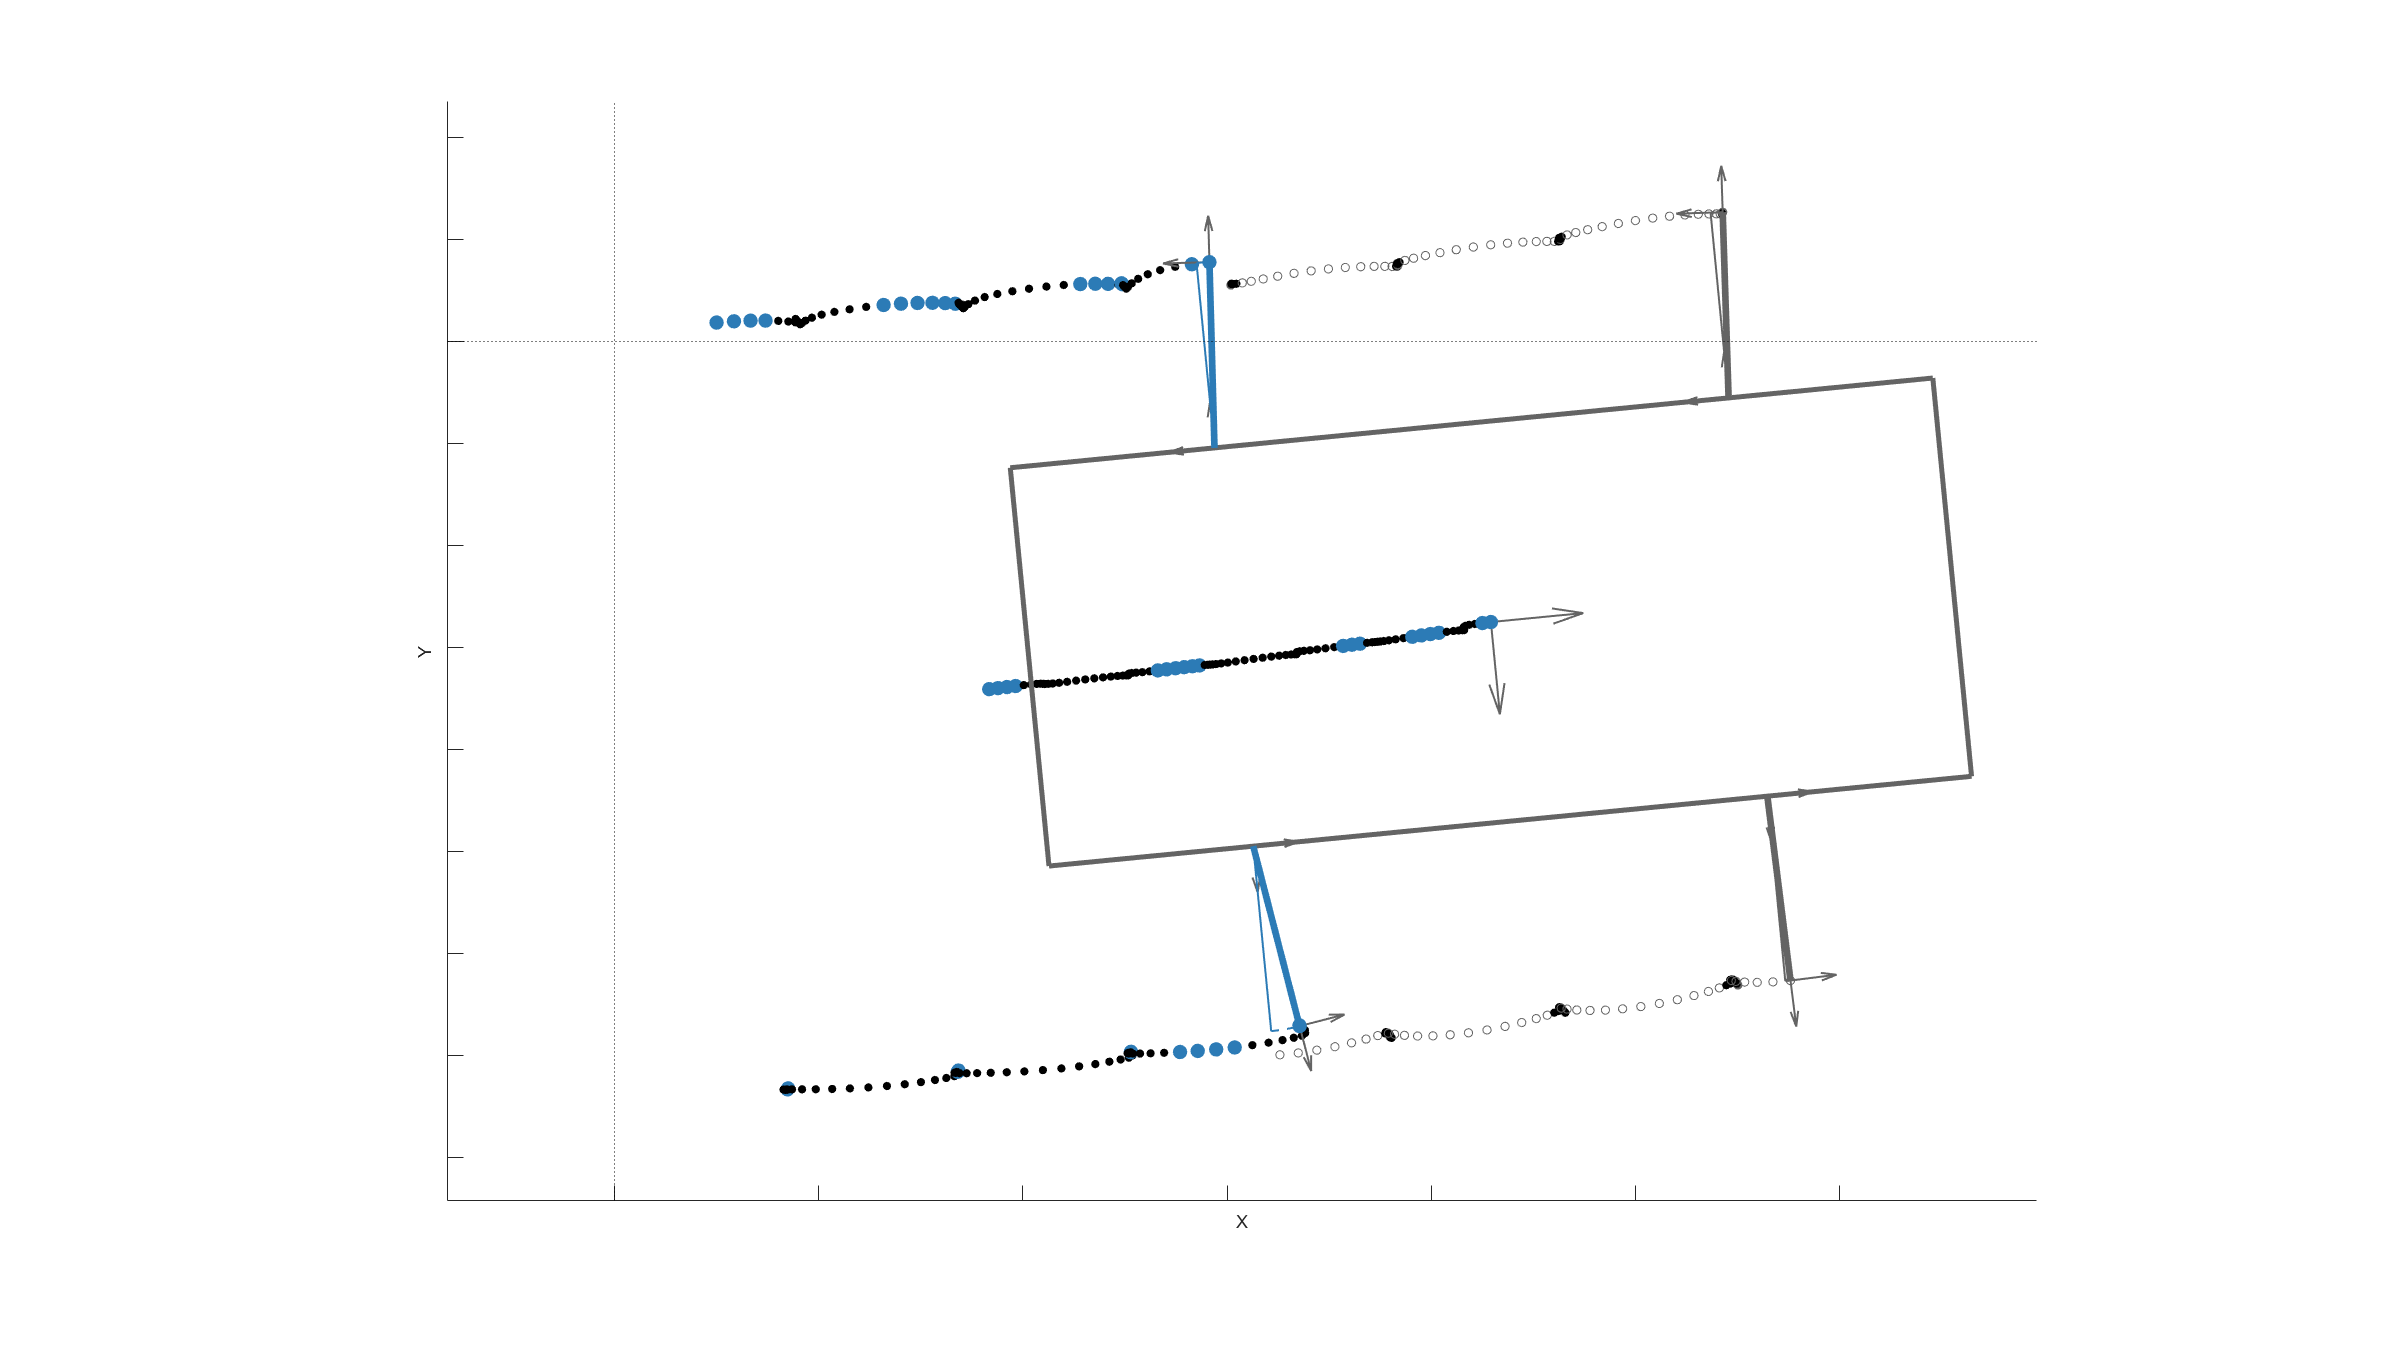

[r1, ~] = genSine_r_rdot(trot.est.r1_params(1:2:end), trot.exp.t);
trot_SE2_est = computeSE2trajectory(r1, trot.est.b1, HAMR_6.SE2); % just the swing trajectory and ESTIMATED body trajectory
trot_SE2_est.bl = bl; % add the body length data
trot_SE2_est.exp = [];
trot_SE2_est.exp.col = trot.exp.col; trot_SE2_est.exp.C_i = trot.exp.C_i; % add some more stuff to the structure for animation
trot_SE2_est.exp.t = trot.exp.t;
trot_SE2_est.exp.tnum = trot.exp.tnum;
v = [];
v.FrameRate = floor( (trot_SE2_est.exp.tnum - 1)/(trot_SE2_est.exp.t(end) - trot_SE2_est.exp.t(1)) );
if v.FrameRate > 60
    v.Speed = round(60/v.FrameRate, 3);
    v.FrameRate = 60;
end
v.Quality = 100;
save_name = [dataset_str '_Trot_' num2str(trot_f{expn}) 'Hz_Run' num2str(idx) '__comp_H2'];
v.Name = [save_addr save_name];
v.VidF = true; % -------------------- % unset this if you don't want a video
animateSE2sys(trot_SE2_est, v);

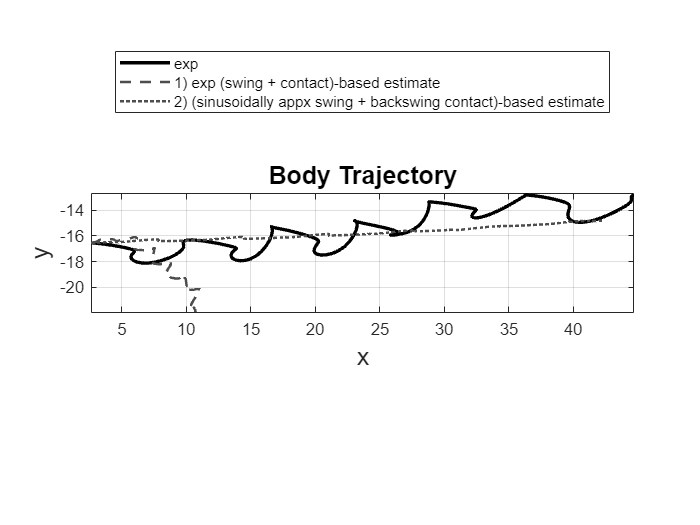

figure(); ax = gca; ax.FontSize = 15; 
plot(trot.exp.b{1}, trot.exp.b{2}, 'k-', 'LineWidth', 2.0, 'DisplayName', 'exp');
hold on; grid on; axis equal tight;
plot(trot.est.b0{1}, trot.est.b0{2}, '--', 'Color', [77, 77, 77]/255, 'LineWidth', 1.5, 'DisplayName', '1) exp (swing + contact)-based estimate');
plot(trot.est.b1{1}, trot.est.b1{2}, ':', 'Color', [77, 77, 77]/255, 'LineWidth', 1.5, 'DisplayName', '2) (sinusoidally appx swing + backswing contact)-based estimate');
legend('location', 'best');
xlabel('x', 'FontSize', 15); ylabel('y', 'FontSize', 15); title('Body Trajectory', 'FontSize', 15);

Animate this body trajectory estimate!

Plot the trajectory slices on iso-$k^2$ level sets.

The final step would be to run the no-slip approximation for the current trajectory.

[trot.est.r2, trot.est.r2_dot] = ...
    generateNoslipTrajectory(kin.dpsi_ij_s_vector, trot, {hamr_a, hamr_l, 'j'}, 'trot'); % jth swing trajectories are kept constant

Let's now compute and plot the corresponding body trajectory.

warning('off');
trot.est.b2 = Path2.estimate_SE2_trajectory( trot, {J, hamr_a, hamr_l, 0.01*bl}, 2 ); % , 'j'
warning('on');

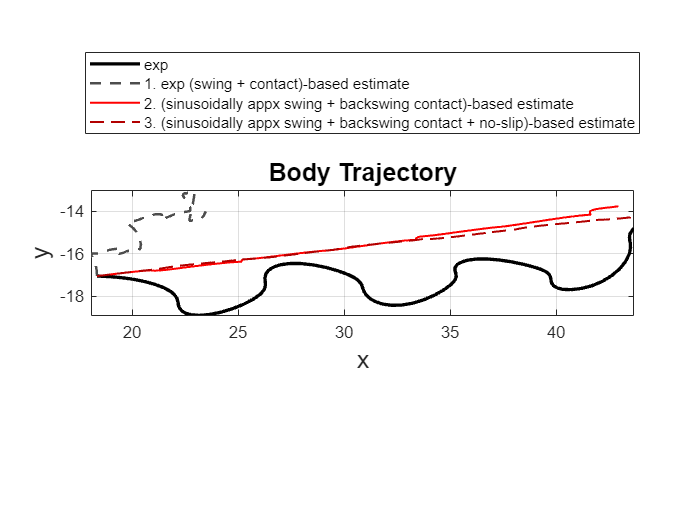

f = figure(); ax = gca; ax.FontSize = 15; 
plot(trot.exp.b{1}, trot.exp.b{2}, 'k-', 'LineWidth', 2.0, 'DisplayName', 'exp');
hold on; grid on; axis equal tight;
plot(trot.est.b0{1}, trot.est.b0{2}, '--', 'Color', [77, 77, 77]/255, 'LineWidth', 1.5, 'DisplayName', '1. exp (swing + contact)-based estimate');
plot(trot.est.b1{1}, trot.est.b1{2}, 'r-', 'LineWidth', 1.2, 'DisplayName', '2. (sinusoidally appx swing + backswing contact)-based estimate'); % , 'Color', [77, 77, 77]/255
plot(trot.est.b2{1}, trot.est.b2{2}, '--', 'Color', [178, 0, 0]/255, 'LineWidth', 1.2, 'DisplayName', '3. (sinusoidally appx swing + backswing contact + no-slip)-based estimate'); %^ %, 'MarkerSize', 1
legend('location', 'best');
xlabel('x', 'FontSize', 15); ylabel('y', 'FontSize', 15); title('Body Trajectory', 'FontSize', 15);
save_name = [dataset_str '_Trot_' num2str(trot_f{expn}) 'Hz_Run' num2str(idx) '__comp_H1_2_3'];
exportgraphics(f, [save_addr save_name '.png'], 'Resolution', 600);
saveas(f,  [save_addr save_name], 'svg');
exportgraphics(f, [save_addr save_name '.pdf'], 'Resolution', 600, 'ContentType', 'vector');

savefig(f, [save_addr save_name '.fig'], 'compact');

Animate this body trajectory estimate!

Plot the trajectory slices on iso-$k^2$ level sets.